# Topics on image formation

- Visual angle

- Circle of confusion

- Linespread function and convolution

- Harmonic functions and blurring

- Pointspread functions

- Chromatic aberration

- Defocus and f-numbers

See also: hwImageFormationHuman for the m-file version of these ideas.

**Date**: 01.02.96 (First drafted) 

**Duration**: 90 minutes

## Initialize ISET

At some point, I will tell you what this does.  But for now, just take it as an initialization of the ISET tools.  As you will see below, we often use 'ie' at the beginning of ISET functions.  This is called making them a 'name space'.  

ieInit;

## Visual angles

There are various ways to specify the physical characteristics of an image. Engineers often describe the image in terms of the physical size and distance, say a paper 25 cm wide at a distance of 0.5 m from the camera.

Vision scientists find it very useful to specify the image in terms of the visual angle the image sweeps out at the camera (or eye). There is a relationship between the physical description of the object and the the degrees of visual angle. Suppose we read the paper at a viewing distance (meters)

viewingDistance = 0.5

viewingDistance = 0.5000


% Imagine a character that is 50 mm (0.05 m) high
imageHeight = 0.05

imageHeight = 0.0500

## Geometric angle calculation

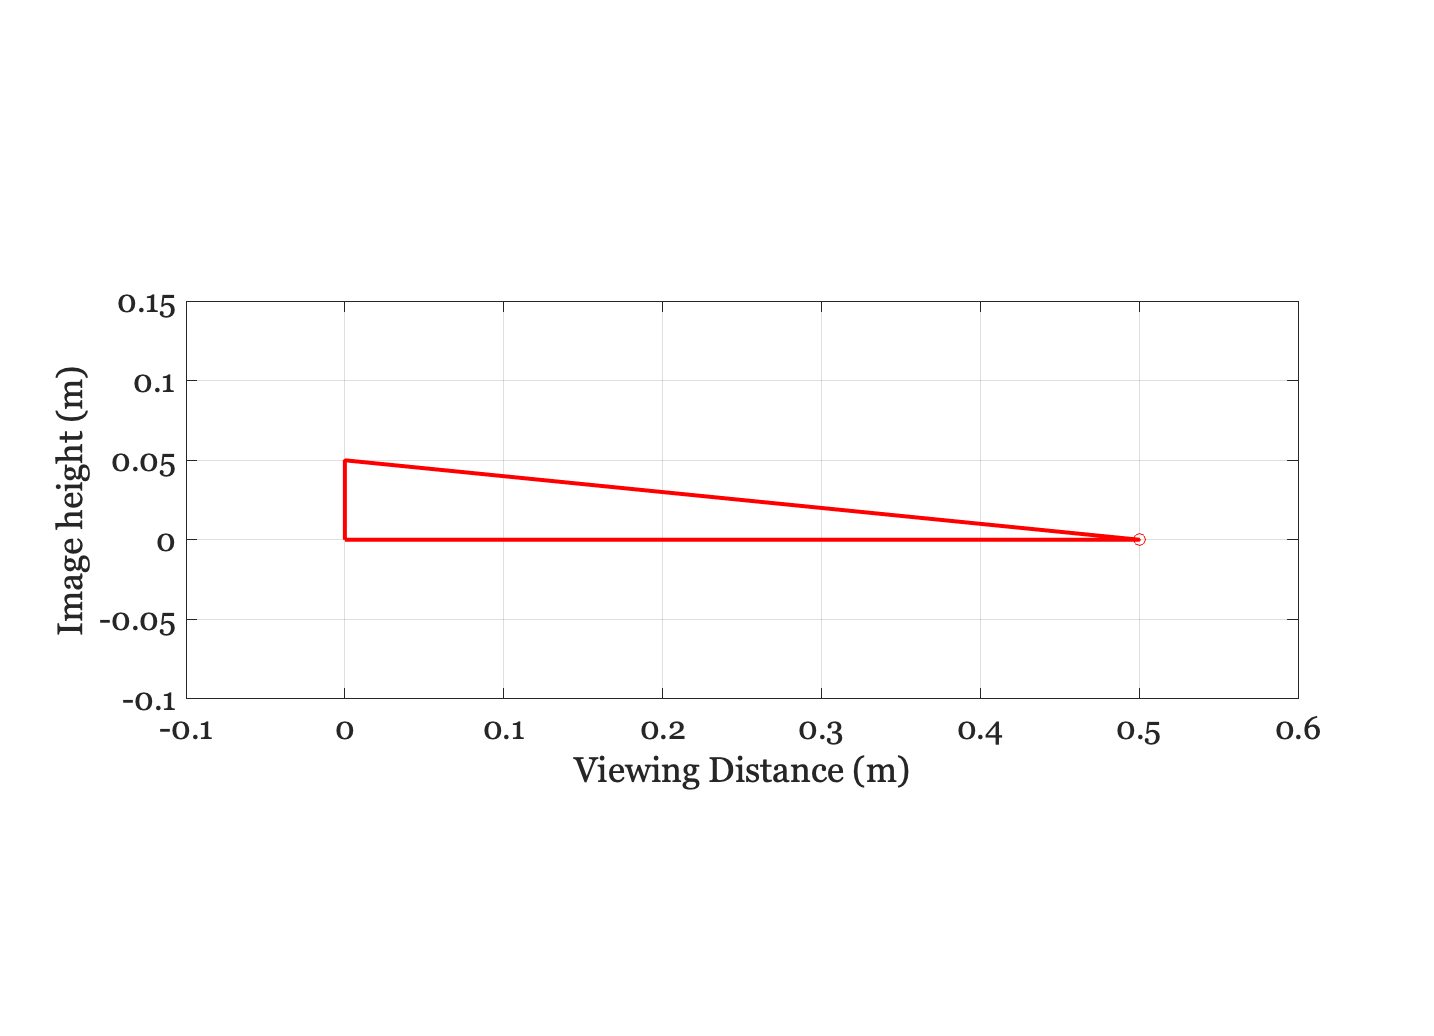

ieNewGraphWin;
plot(viewingDistance,0,'o'); hold on
thisL = line([0 viewingDistance 0 0],[0 0 imageHeight 0]);
thisL.LineWidth = 2;
axis equal
set(gca,'xlim',[-0.1 viewingDistance + 0.1],'ylim',[-0.1 imageHeight + 0.1]), grid on
xlabel('Viewing Distance (m)')
ylabel('Image height (m)')
grid on

In degrees, the viewing angle, phi, satisfies


$$\tan \left(\phi \right)=\frac{\textrm{opposite}}{\textrm{adjacent}}$$


phi = atand(imageHeight/viewingDistance)

phi = 5.7106


% Suppose we are looking at a printer with 600 dots per inch (dpi). Oddly, dpi is a
% common specification for printers
dpi = 600;

% ISET has a convenient function to convert these units into meters per dot.
meterPerDot = dpi2mperdot(dpi,'meters');

% So there are this many dots in the imageHeight
nDots = imageHeight/meterPerDot;

% and each dot takes up this many degrees of visual angle (for small angles)
degPerDot = phi/nDots;

% There are 60 min of visual angle per deg,
minPerDot = 60*degPerDot;

% and 60 sec of visual angle per min,
secPerDot = 60*minPerDot;


Perceptual experiments show that people see a difference between two lines that are offset by 6 sec of visual angle.  Hence, the dot spacing is wider than the spacing that can be discriminated by people. 

At this point, you can answer several of the questions in "Homework 1: Image Formation."

## The Westheimer linespread function

Westheimer was one of the first to estimate the linespread function of the human optics. He specified the spread of light at the back of the eye when the input is a line.  He specified the line spread in terms of a variable, x,  in minutes of arc.  For a 3mm pupil size (and the pupil size matters) he proposed the formula


$$\textrm{ls}\left(x\right)=0\ldotp 47*\exp \left(-3\ldotp 3*x^2 \right)+0\ldotp 53*\exp \left(-0\ldotp 93*\textrm{abs}\left(x\right)\right)$$


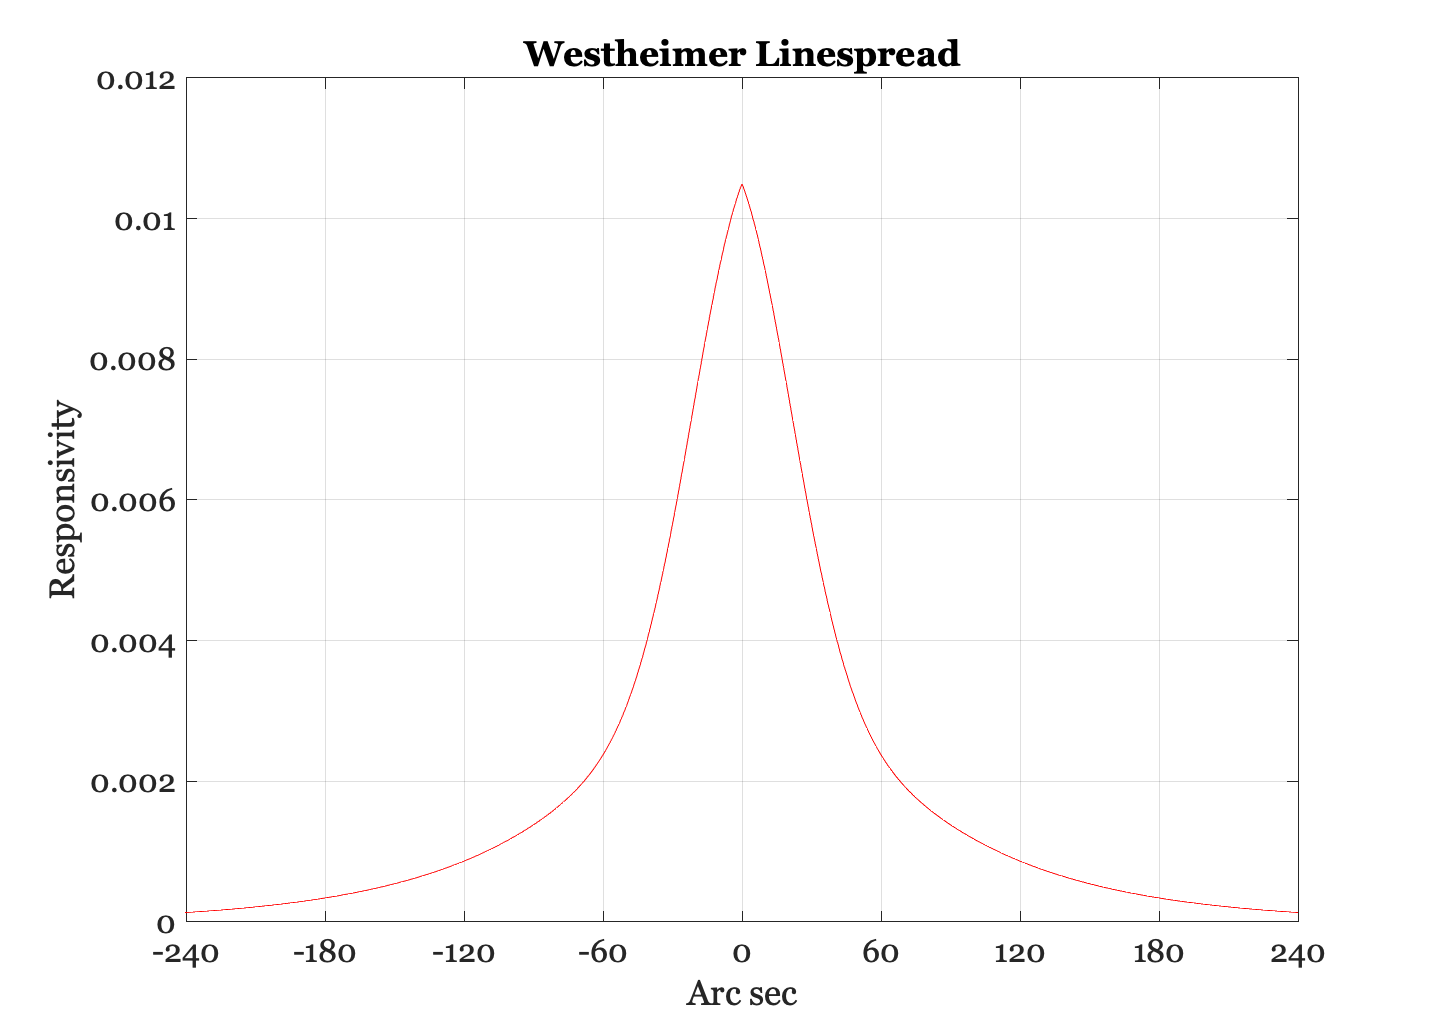

% Suppose we plot the linespread function at a slightly finer spatial resolution, 
% in seconds of arc. 
xSec = -300:1:300;

% To use the functional form from Westheimer we convert the units to minutes of arc
xMin = xSec/60;
ls = 0.47*exp(-3.3 *(xMin.^2)) + 0.53*exp(-0.93*abs(xMin));

% And we normalize the ls assuming that no light is lost.
ls = ls / sum(ls);

ieNewGraphWin;
plot(xSec,ls)
set(gca,'xlim',[-240 240],'xtick',(-240:60:240)), grid  on
xlabel('Arc sec'), ylabel('Responsivity'), title('Westheimer Linespread')

## Thought question

In the previous section, we calculated the spacing of the dots in a 600 dpi printer (secPerDot). Compare that spacing with the sec of visual angle apart.  Does this linespread help you think about whether this separation of two points should be visible to a person?

## The Westheimer function and the Fourier Transform (FFT)

The modulation transfer function (MTF) describes how the amplitude of each harmonic is scaled by the optics.  If we know the linespread function, we can calculate the MTF using the Fast Fourier Transform. In this code snippet, we use the function westheimerLSF to estimate the human MTF.  That function takes its input as a spatial variable in sec of arc

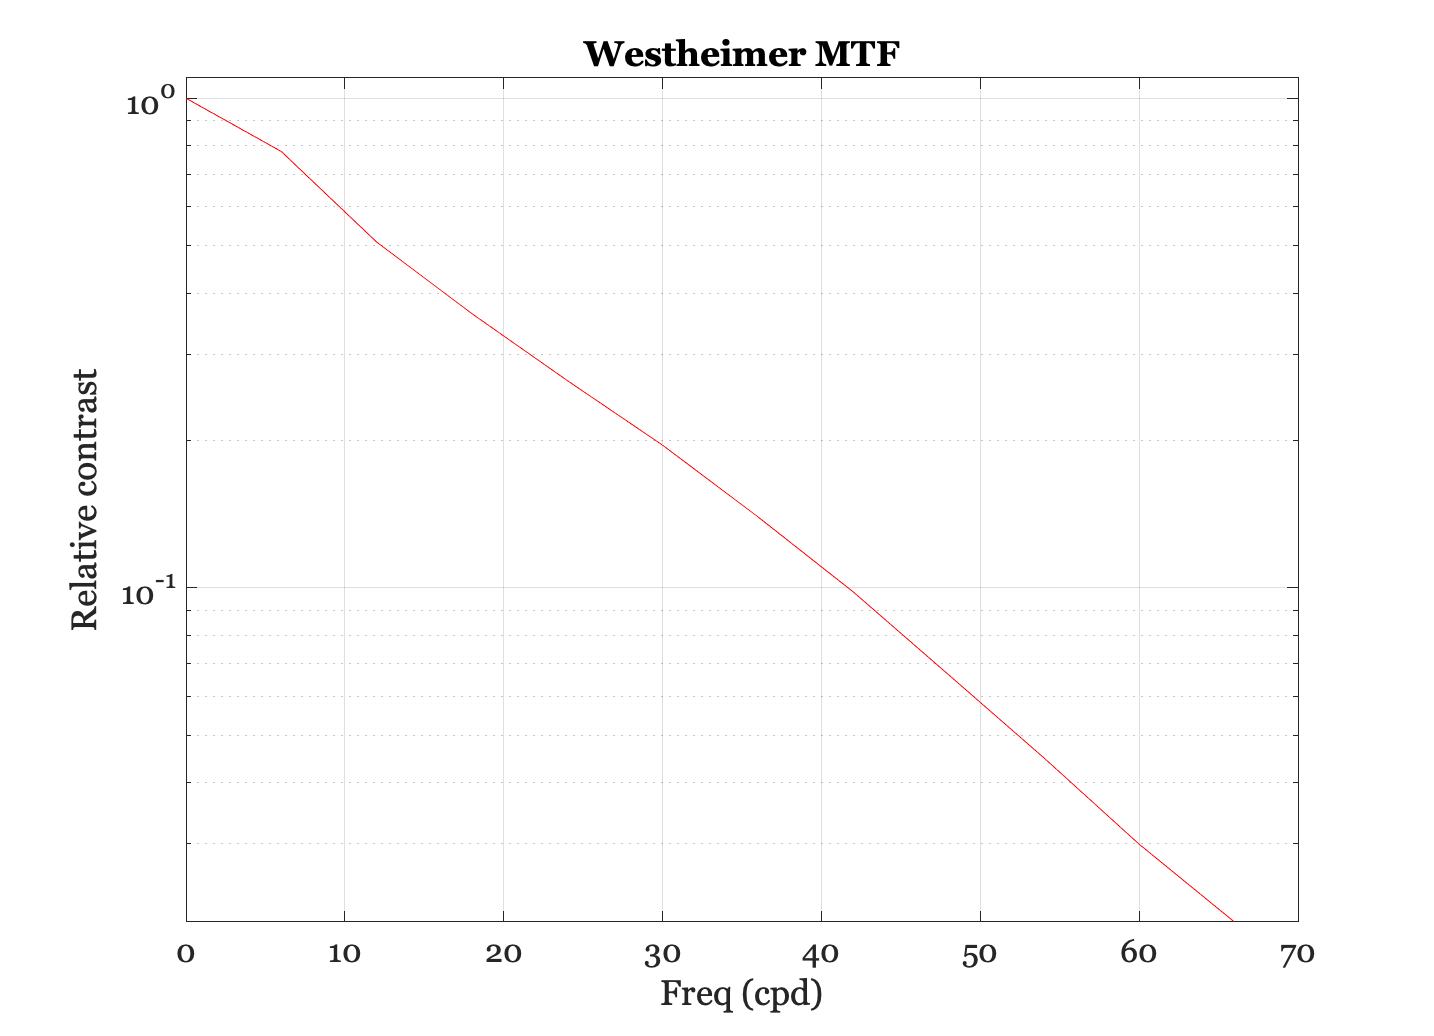

xSec = -300:300;    % 600 sec, total = 10 arc min
westheimerMTF = abs(fft(westheimerLSF(xSec)));

% One cycle spans 10 min of arc, so freq=1 is 6 c/deg
freq = (0:11)*6;
ieNewGraphWin;
semilogy(freq,westheimerMTF(1:12)); grid on;
xlabel('Freq (cpd)'); ylabel('Relative contrast');
set(gca,'ylim',[0 1.1])
title('Westheimer MTF');

## Convolution of the image and linespread

We can estimate the retinal image from a document printed at 600 dpi using the following simple convolution calculation. Suppose the image spans 0.2 deg and has a dot every 30 arc sec.

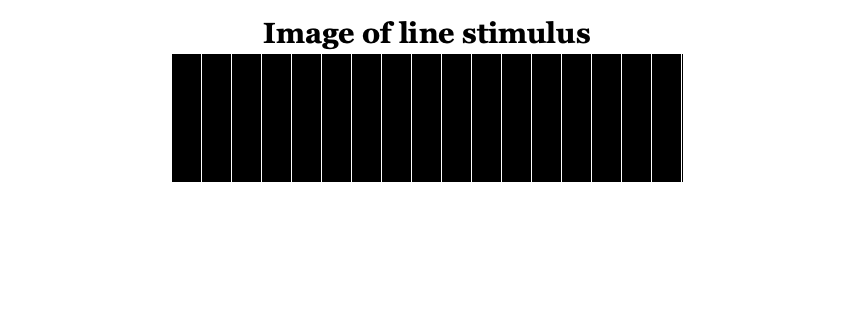

% Make a 1-d image
imageWidth = 0.2;               % deg
secPerDeg = 60*60;
x  = 1:(imageWidth*secPerDeg);  % arc sec
im = zeros(1,length(x));

dotSpacing = 30;                % arc sec
im(1:dotSpacing:length(im)) = ones(size(im(1:dotSpacing:length(im))));

% Here is an image showing the sampled line positions
% (The lines represent a printer dot)
ieNewGraphWin;
imshow(im(ones(1,128),1:512))
title('Image of line stimulus');

Each line in the physical image adds a unit linespread to the retinal image.  We can compute the retinal image by forming the convolution of the image with the Westheimer linespread function.  Remember: we sampled the linespread once every sec of arc. So, we can  convolve the image and the linespread function 

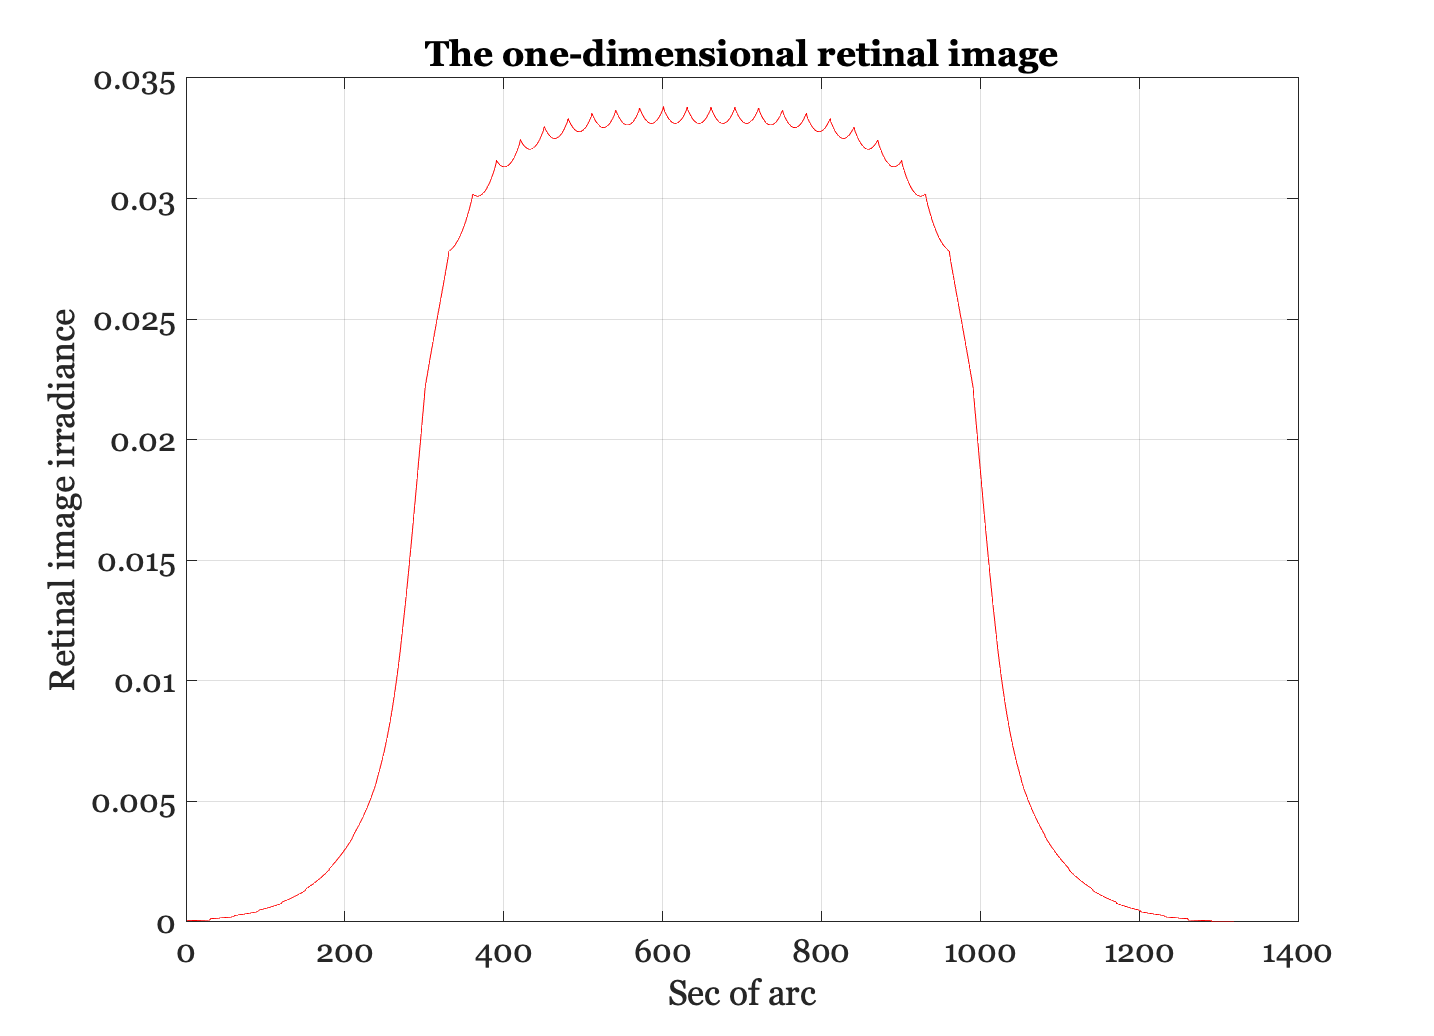

retIm = conv2(ls,im,'full');

ieNewGraphWin;
plot(retIm),grid on
title('The one-dimensional retinal image')
xlabel('Sec of arc'), ylabel('Retinal image irradiance')

While the original image varies from black to white, after blurring by the eye's optics, there is only a small amount of residual variation in the retinal image.  Because of the blurring, the retinal image is much more likely the image of a bar than it is the image of a set of individual lines.

In fact, the dots placed on the page are not perfect line samples.  Each ink line has some width.  So, a more realistic input image might be created by blurring the stimulus and then convolving with the linespread.

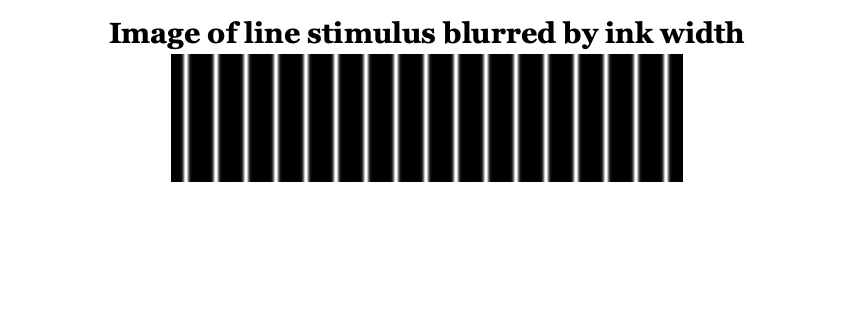

% This produces a little Gaussian window for filtering
gKernel = fspecial('gaussian',[1,30],2);
blurIm = conv2(im,gKernel,'full');     % Ink blur on page
retIm  = conv2(blurIm,ls,'full');      % Now the eye

ieNewGraphWin;
imshow(blurIm(ones(1,128),1:512),[]);
title('Image of line stimulus blurred by ink width');

Notice the very small ripples left in the curve after taking into account the blurring by the physical display and by the eye.

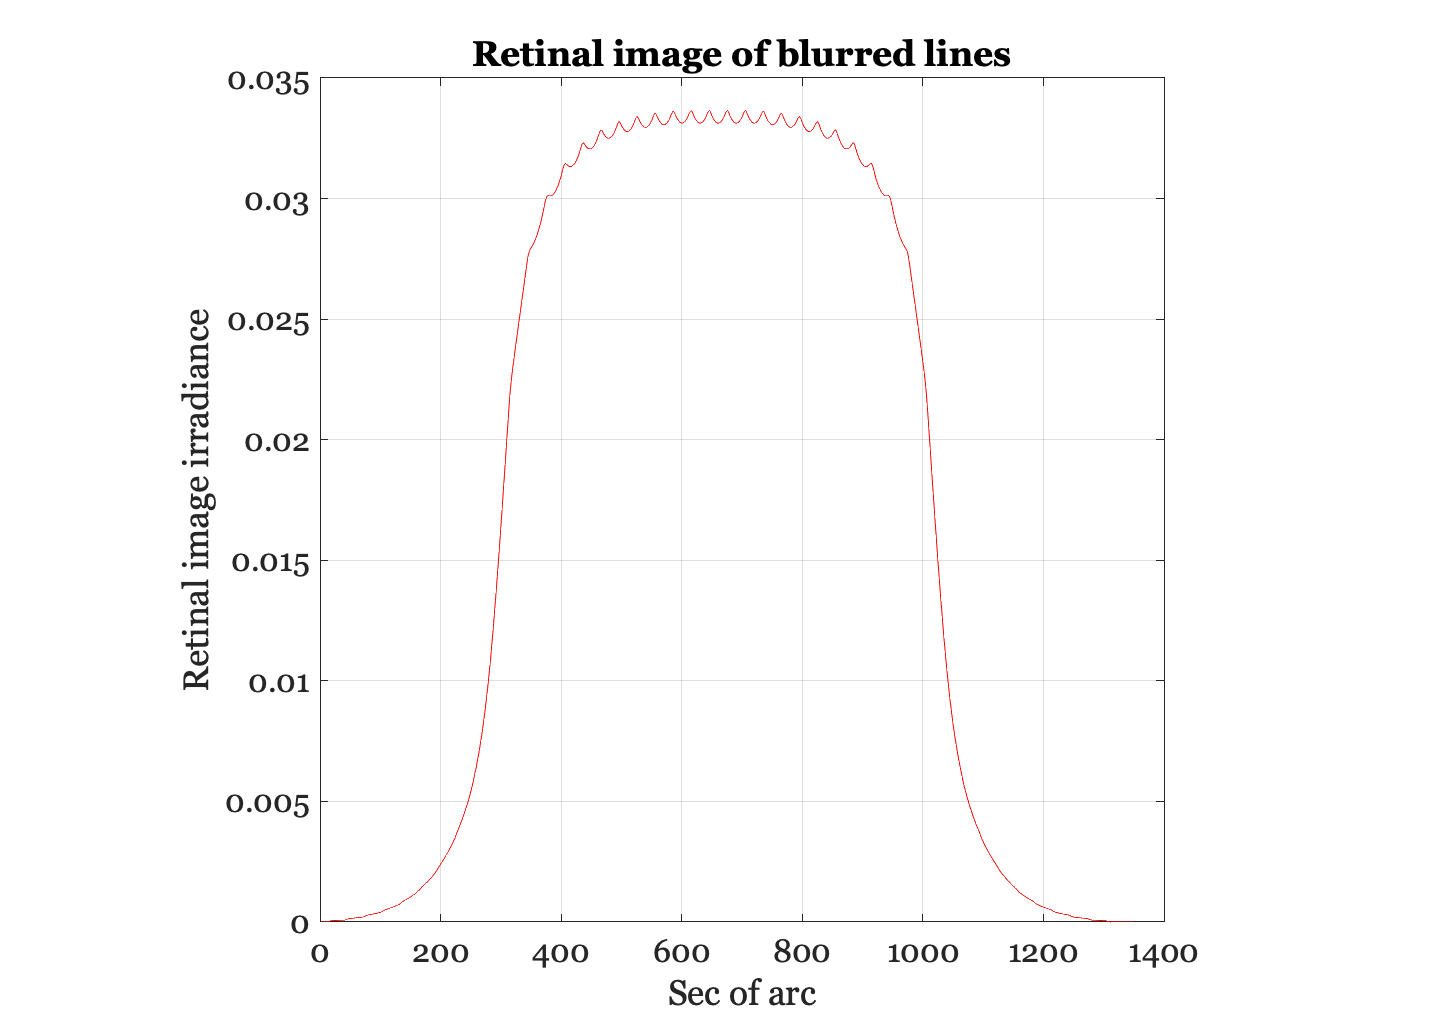

ieNewGraphWin;
plot(retIm), axis square, grid on
title('Retinal image of blurred lines')
xlabel('Sec of arc'), ylabel('Retinal image irradiance')

## Thought question

The question you might ask yourself now is this: will those small ripples be detectable by people looking at the screen?  How can we tell? You might also ask what will happen when we view the page at 6 inches, or at 24 inches.  What if we increase the printer resolution to 1200 dpi?  What if we introduce some ability to modulate the density of the ink and hence the light scattered back to the eye? We can answer these kinds of questions using ISET simulations. 

## The linespread in the frequency domain (MTF)

Let's make a new linespread function that is sampled less finely and thus easier to compute with.  Also, we make it extend over 1 deg (60 min) so the Fourier Transform is easier to interpret

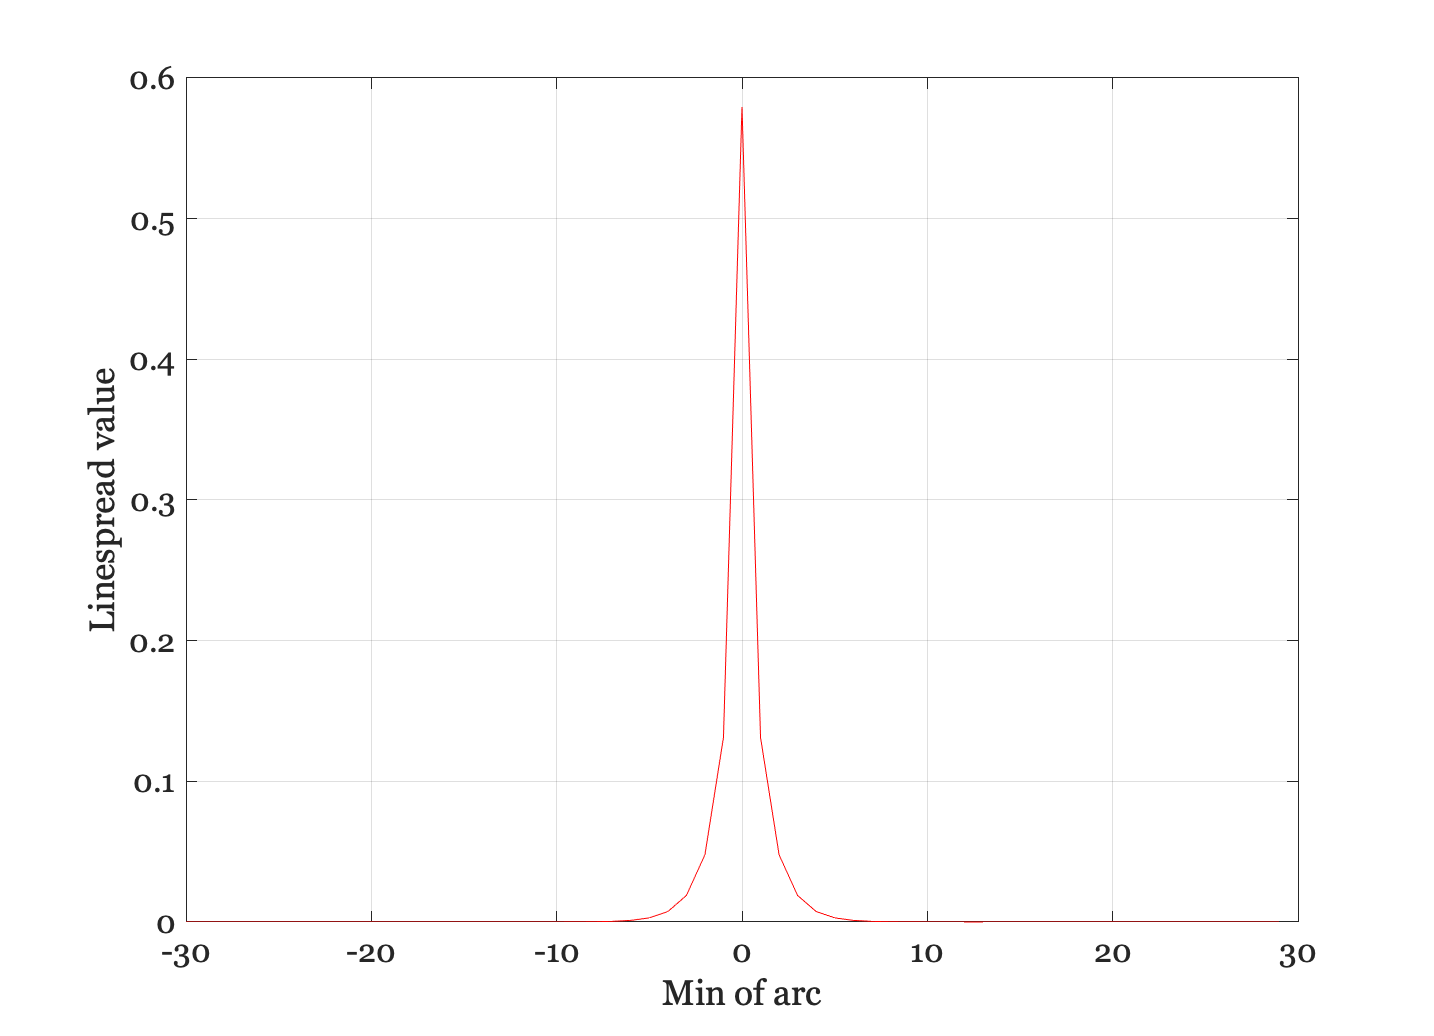

% We often encapsulate formulae that frequently use in functions. The
% Westheimer function was useful for some years and so here it is.
xMin = -30:1:29;
ls = westheimerLSF(xMin*60);

ieNewGraphWin;
plot(xMin,ls), grid on
xlabel('Min of arc'),ylabel('Linespread value')

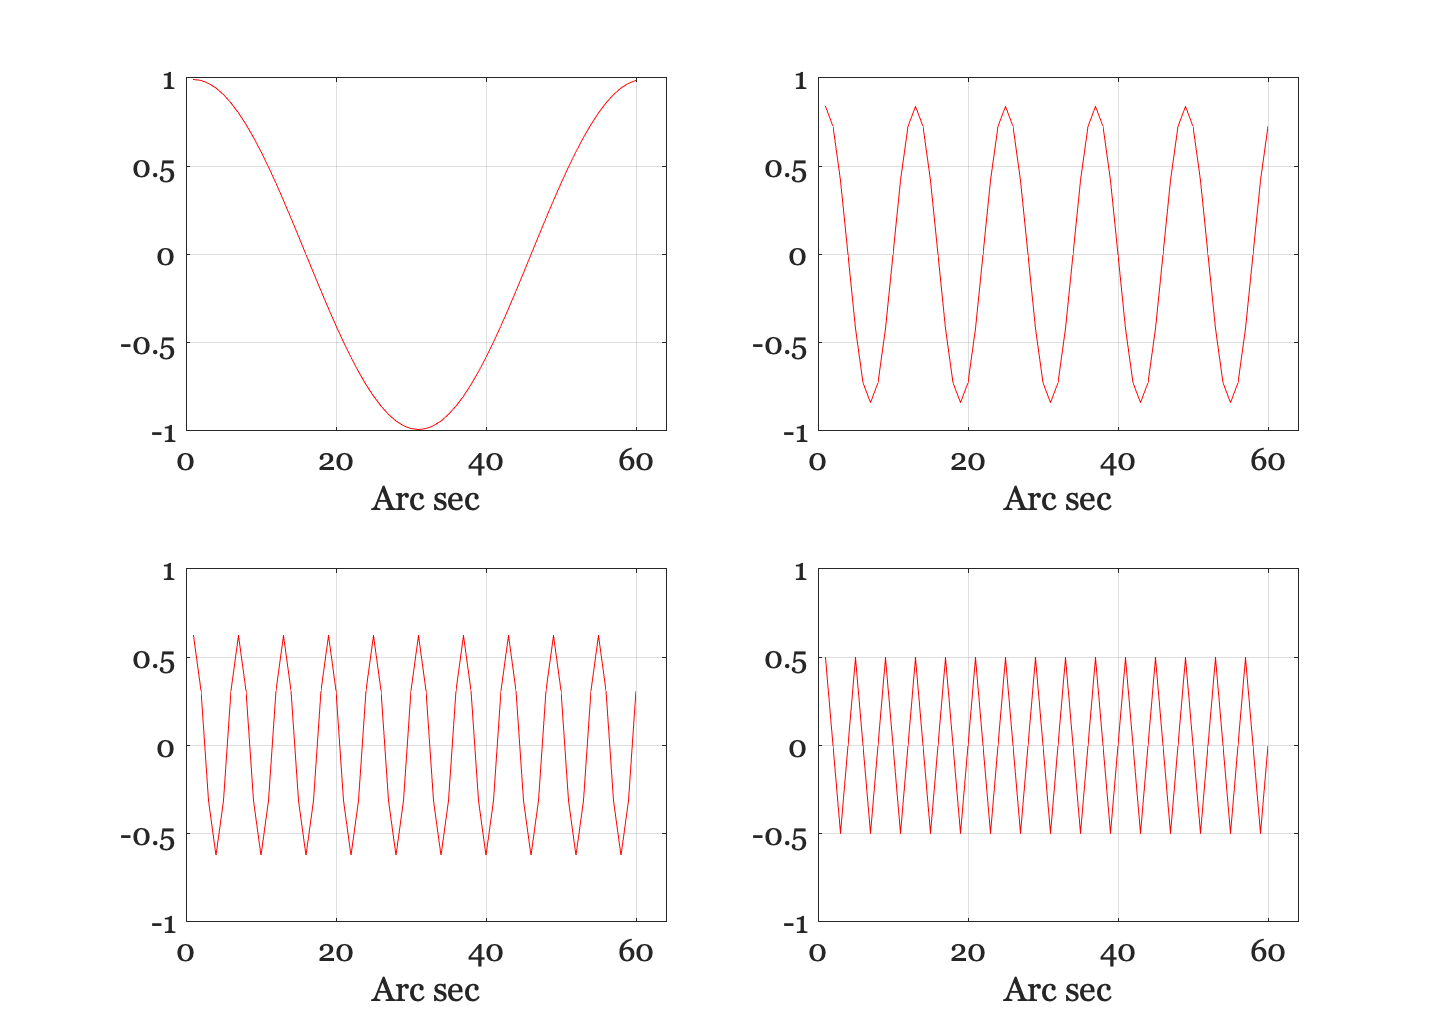

nSamples = length(xMin);

% Now, calculate the retinal image for different harmonics, as the
% frequency increases.  We store the amplitude of the cosinusoid in
% the variable "peak".
ieNewGraphWin;
freq =[1 5 10 15];
peak = zeros(1,length(freq));
for i = 1:length(freq)
    harmonic = cos(2*pi*freq(i)*xMin/nSamples);
    retIm = convolvecirc(harmonic,ls);
    subplot(2,2,i)
    plot(retIm), grid on, set(gca,'ylim',[-1 1],'xlim',[0 64]);
    xlabel('Arc sec')
    peak(i) = max(retIm(:));
end

## MTF - Calculated two ways

Using the above, we can develop some intuition about the MTF. We calculate it in two different ways: first, we plot the amplitude of the retinal cosinusoid, and its amplitude decreases with the input frequency.  Next, we calculate the Fourier Transform of the linespread and plot the values at these frequencies (red circles). 

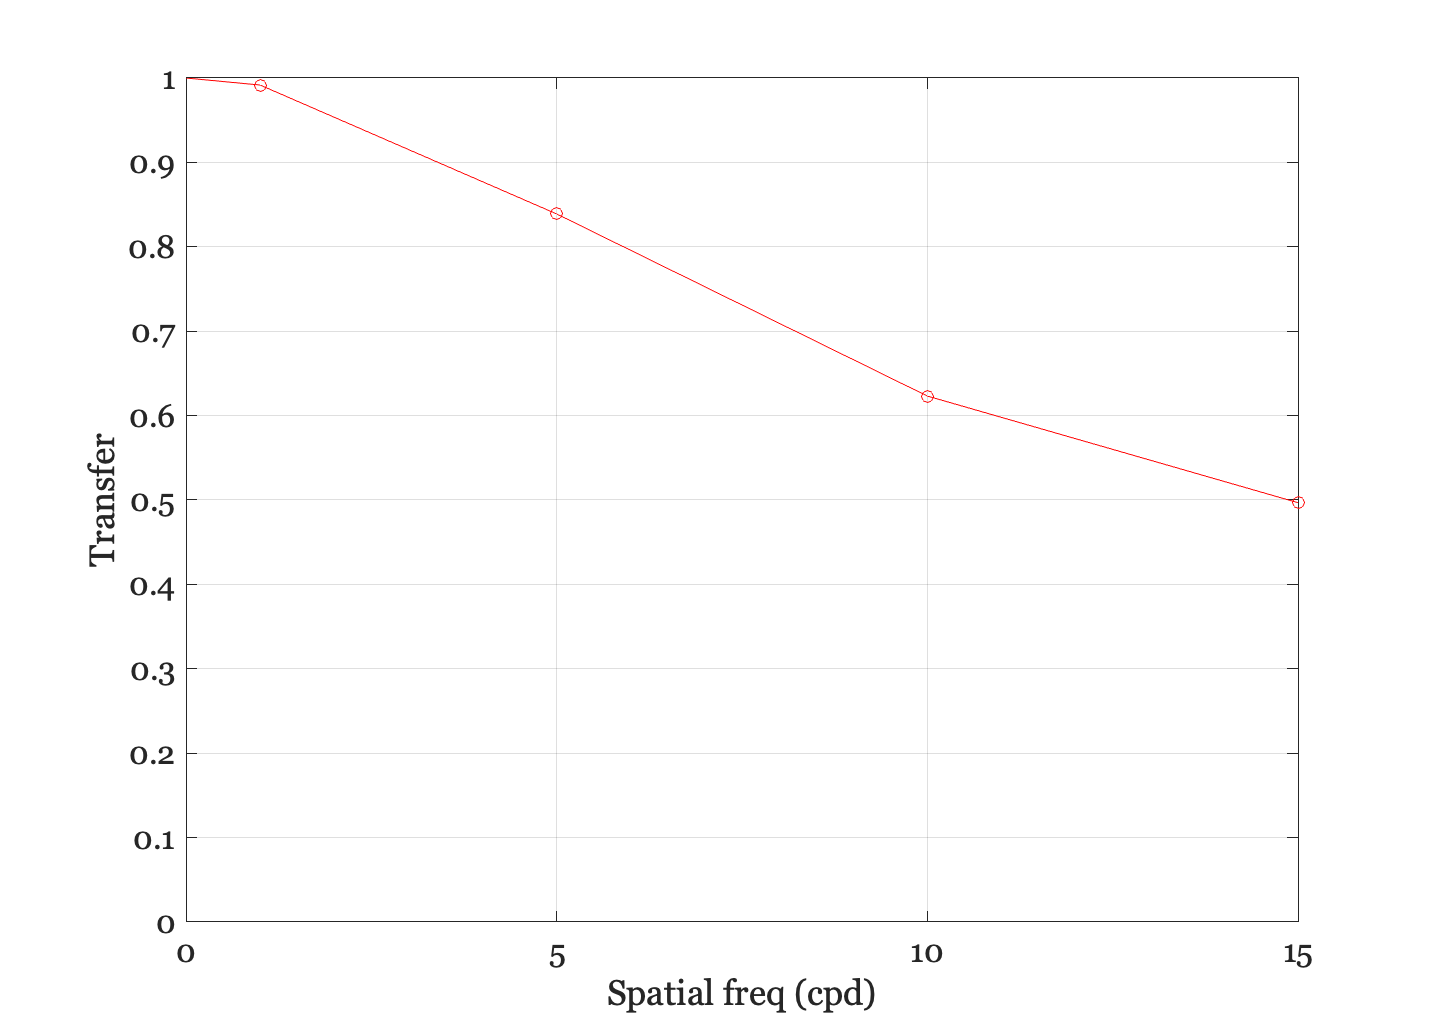

ieNewGraphWin;
plot([0 freq],[1 peak],'-');      % At freq = 0 the MTF is 1, by definition
set(gca,'ylim',[0 1])
xlabel('Spatial freq (cpd)'), ylabel('Transfer')
grid on

% Compare the peak values with the abs(FFT) values
mtf = abs(fft(ls));
hold on, plot(freq,mtf(freq + 1),'ro');
hold off

## The pointspread and linespread

When working with two-dimensional inputs, we must consider the pointspread function, that is the response to an input that is a point of light. A standard formula for the cross-section of the pointspread function of the human eye for a 3mm pupil is also provided by Westheimer.  We can compare the linespread and the cross-section of the pointspread in the following graphs.

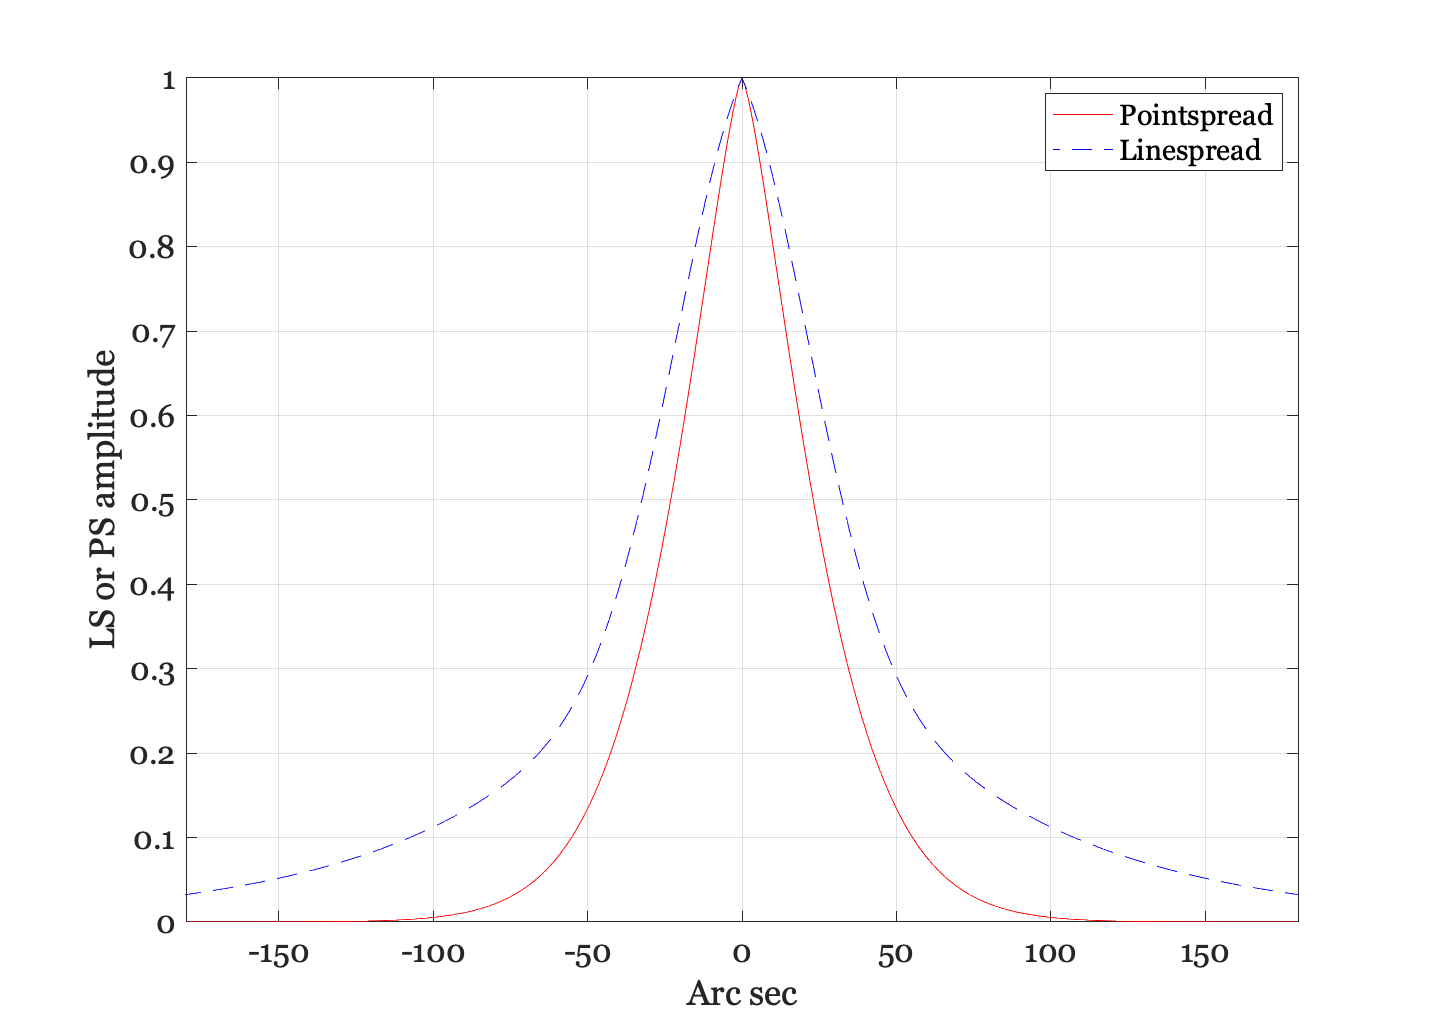

xSec = -300:300;
xMin = xSec/60;
ls = 0.47*exp(-3.3 *(xMin.^2)) + 0.53*exp(-0.93*abs(xMin));
ps = 0.952*exp(-2.59*abs(xMin).^1.36) + 0.048*exp(-2.43*abs(xMin).^1.74);

ieNewGraphWin;
p = plot(xSec,ps,'r-',xSec,ls,'b--'); grid on
set(gca,'xlim',[-180 180])
xlabel('Arc sec'), ylabel('LS or PS amplitude')
legend(p,'Pointspread','Linespread')

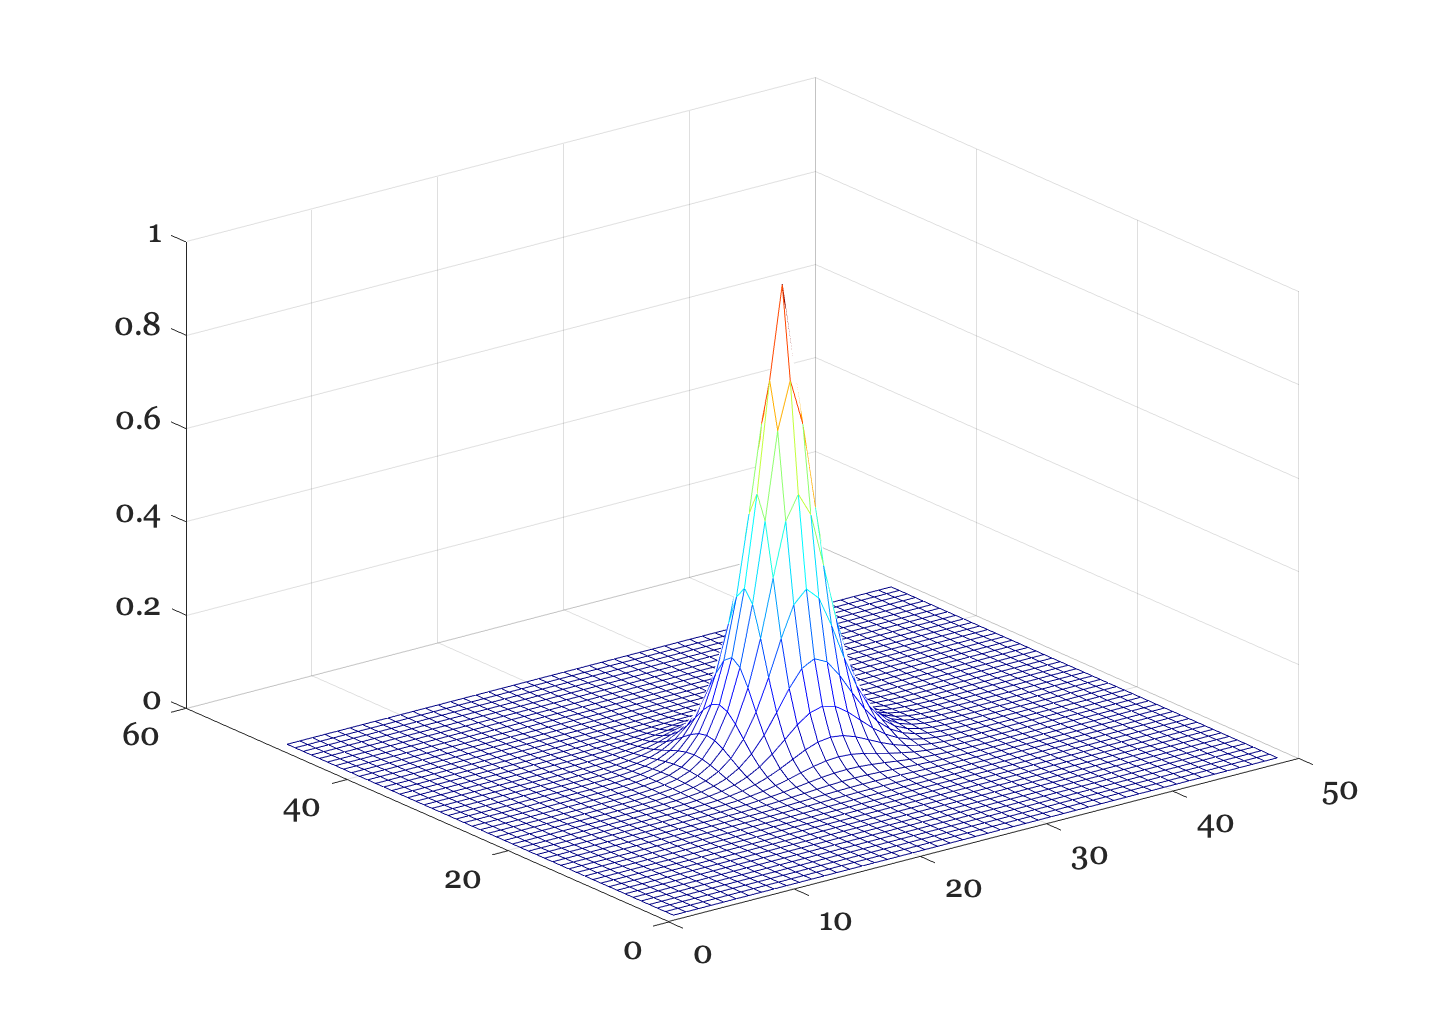


% Next, we create a graph of the pointspread.  First, create
% a matrix whose entries are the distance from the origin
xSec = -240:10:240;
xMin = xSec/60;
X = xMin(ones(1,length(xMin)),:); Y = X';
D = X.^2 + Y.^2; D = D.^0.5;

% If you want to see the distance from the origin, you might show
% this image: colormap(gray(32)),imagesc(D), axis image

% Then, compute the pointspread function and make a picture of it
ps = 0.952*exp(-2.59*abs(D).^1.36) + 0.048*exp(-2.43*abs(D).^1.74);
ieNewGraphWin;
colormap(jet(256)), mesh(ps)


% To see the pointspread as an image, rather than as a mesh plot,
% you might make this figure: colormap(gray(32)),imagesc(ps), axis image

## Chromatic aberration: How the linespread varies with wavelength

The linespread varies quite strongly with wavelength.  When the eye is in good focus at 580 nm (yellow-part of the spectrum) the light in the short-wavelength (400-450nm) is blurred quite strongly and light in the long-wavelength part of the spectrum is blurred, too, though somewhat less.  We can calculate the linespread as a function of wavelength (Marimont and Wandell, 1993) from basic principles.  

The  linespreads a various wavelengths from 370-730nm, in 1nm steps are contained in a data file. The linespreads were generated by the script ChromAb.m. The variable in the file 'xDim' is in degrees of visual angle. The variable 'wave' is in nanometers.

fileName = 'lineSpread';
load(fileName,'lineSpread','xDim','wave');

We select three wavelengths from the lineSpread data and plot their linespread functions together. Notice that for the shorter wavelength, the linespread function is much more spread-out than for the middle and long wavelengths.

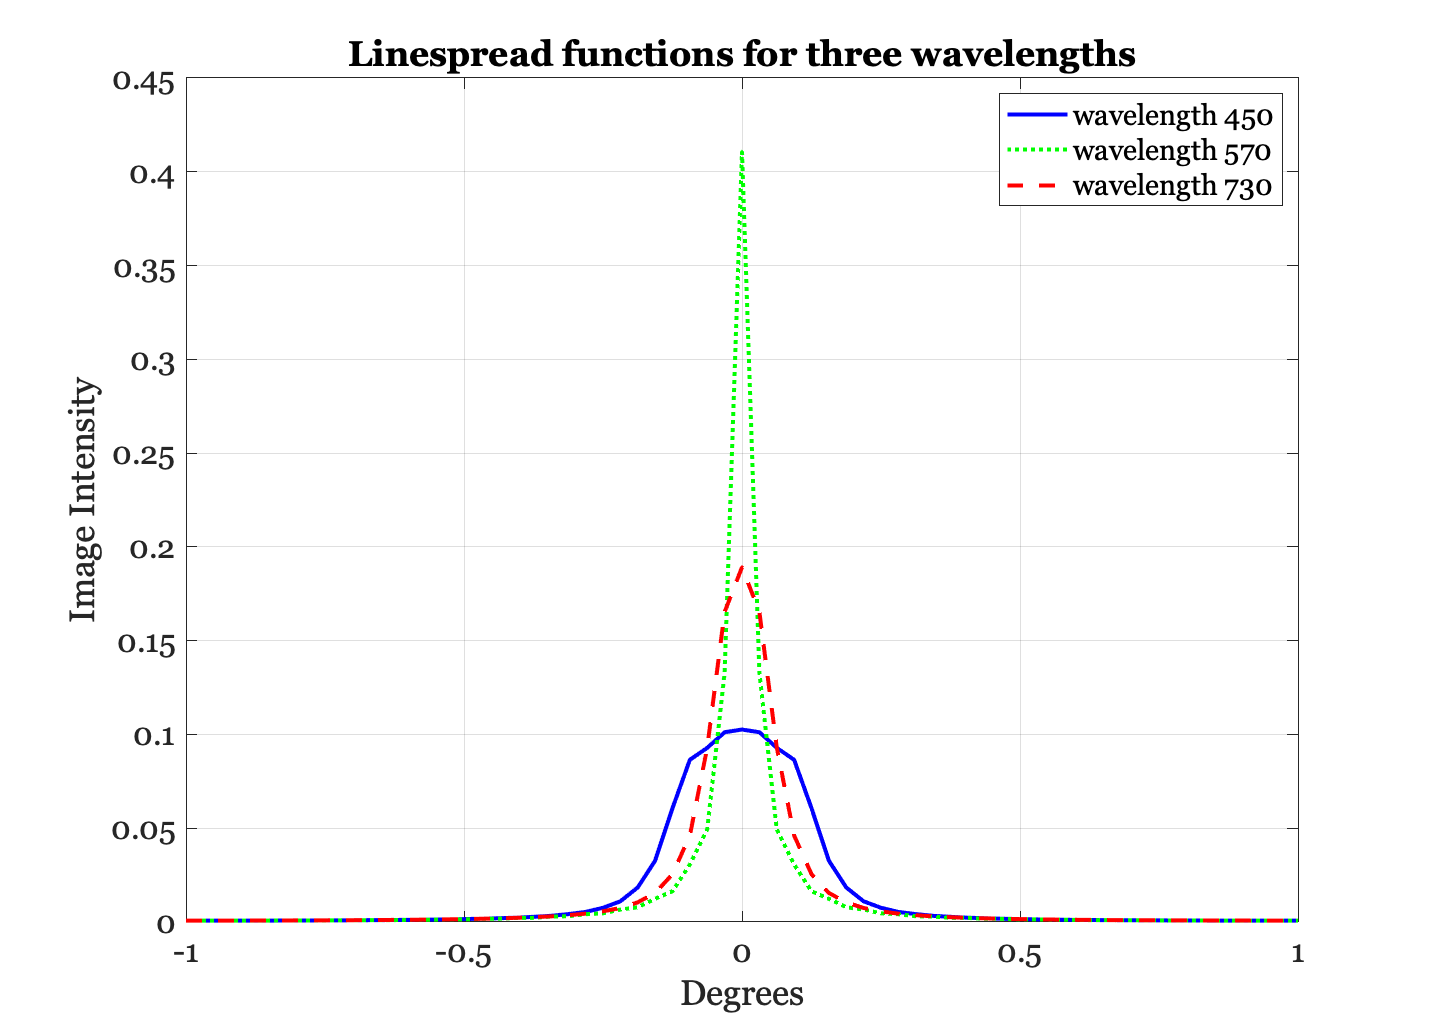

ieNewGraphWin;
plot(xDim, lineSpread(80, :), 'b-', xDim, lineSpread(200,:), ...
    'g:', xDim, lineSpread(361, :), 'r--' ,...
    'lineWidth',2);
legend('wavelength 450', 'wavelength 570','wavelength 730');
xlabel('Degrees'); ylabel('Image Intensity'); grid on
title('Linespread functions for three wavelengths');

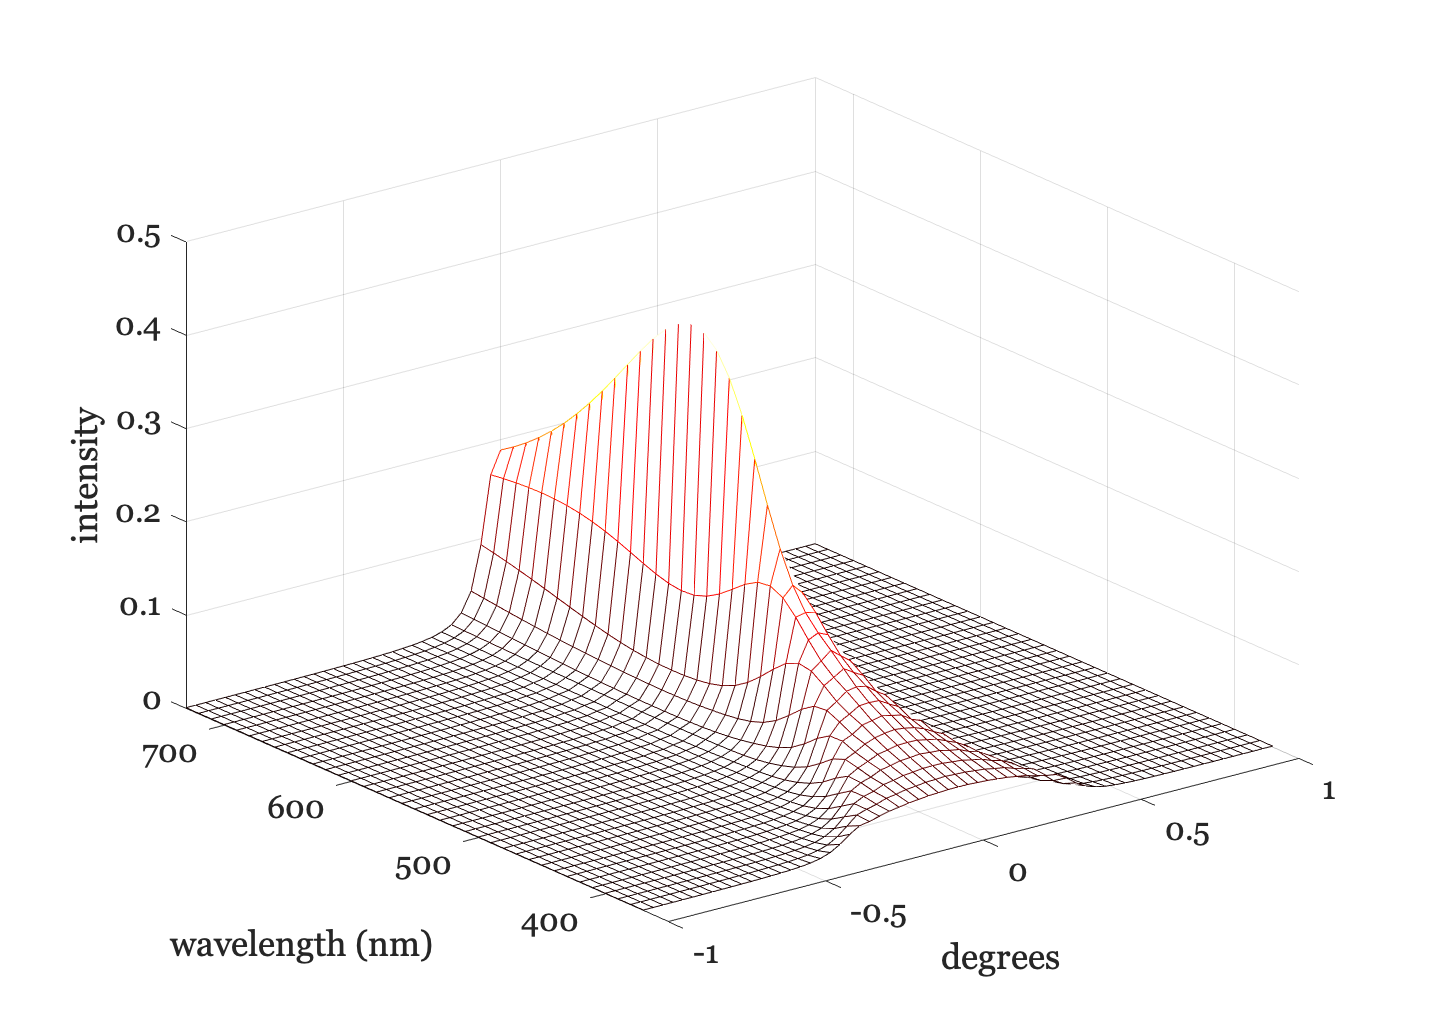


%  Look at the line spread functions for several wavelengths
lw = 1:10:length(wave);
ieNewGraphWin;
colormap(hot(32));
mesh(xDim, wave(lw), lineSpread(lw,:));
set(gca,'xlim',[-1 1],'ylim',[350 730])
ylabel('wavelength (nm)'); xlabel('degrees'); zlabel('intensity');

## Chromatic aberration

Different wavelength components of an image are blurred to different extents by the eye.  We use a set of lines again as an example.  For this computation, we will assume that the input begins with equal energy at all wavelengths from 370 to 730 nm.

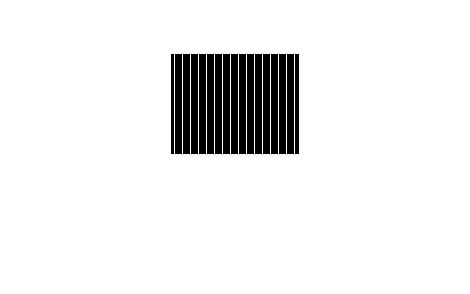


% Create and display the image of sample lines.
im = reshape([0 0 0 1 0 0 0 0]' * ones(1, 16), 1, 128);
imshow(im(ones(100,1), 1:128));

To calculate the retinal image for this pattern, we convolve each wavelength component of the image with the appropriate linespread function.  The routine conv2 takes the input image (im, size(im) = 1 128) and convolves it with each of the linespread functions in lineSpread size(lineSpread = 361,65).  This results in 361 images (one for each wavelength).


retIm = conv2(im, lineSpread, 'full');

% We remember the size (in deg) of each sample point this way.
X = (-size(retIm,2)/2 : ((size(retIm, 2)/2) - 1)) / 64;


We plot the retinal image corresponding to two wavelengths. The short wavelength (420 nm) component is blurred much more than the longer wavelength component of the image.  Hence, the image has very low amplitude ripples, and appears almost like a single, uniform bar.  The 570nm component, however, has high amplitude ripples that are quite distinct.  Hence, the short-wavelength variation would be very hard to detect in the retinal image, while the 570 nm component would be quite easy to detect.

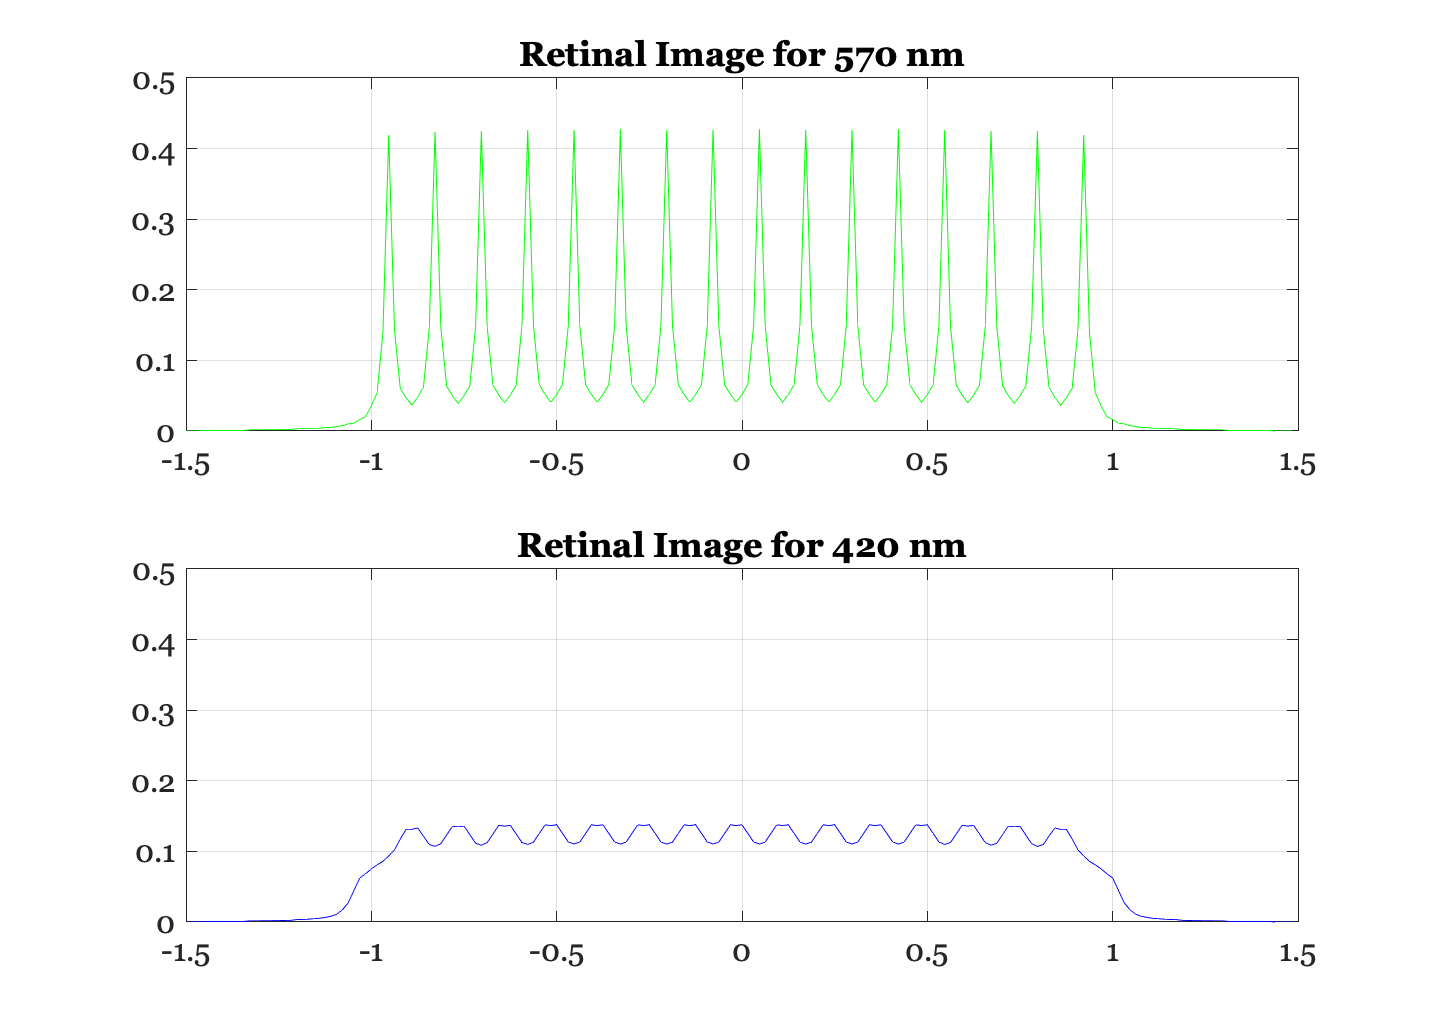


ieNewGraphWin;
subplot(2,1,1)
plot(X,retIm(201,:),'g-')
set(gca,'ylim',[0 0.5])
title(sprintf('Retinal Image for %d nm', wave(201)));
grid on

subplot(2,1,2)
plot(X,retIm(51,:),'b-')
set(gca,'ylim',[0 0.5])
title(sprintf('Retinal Image for %d nm', wave(51)));
grid on


% Notice that the two images have the same mean, they only differ
% in terms of the contrast:  the green image has a lot more
% contrast, but the same mean.
mean(retIm(50,:),2)

ans = 0.0833

mean(retIm(200,:),2)

ans = 0.0833

At this point, you can answer Questions #3 on "Homework 1: Image Formation."

## Chromatic aberration in the frequency domain

Finally, let's make a few graphs of the modulation transfer function of the eye's optical system for individual wavelengths.  For short wavelength lights, high spatial frequency contrast is attenuated a lot by the optical path of the eye. 

Load the MTFs for wavelengths from 370-730nm.  These were calculated using the methods in Marimont and Wandell that are in a script in the /local/class/psych221/tutorials/chromAb sub-directory.

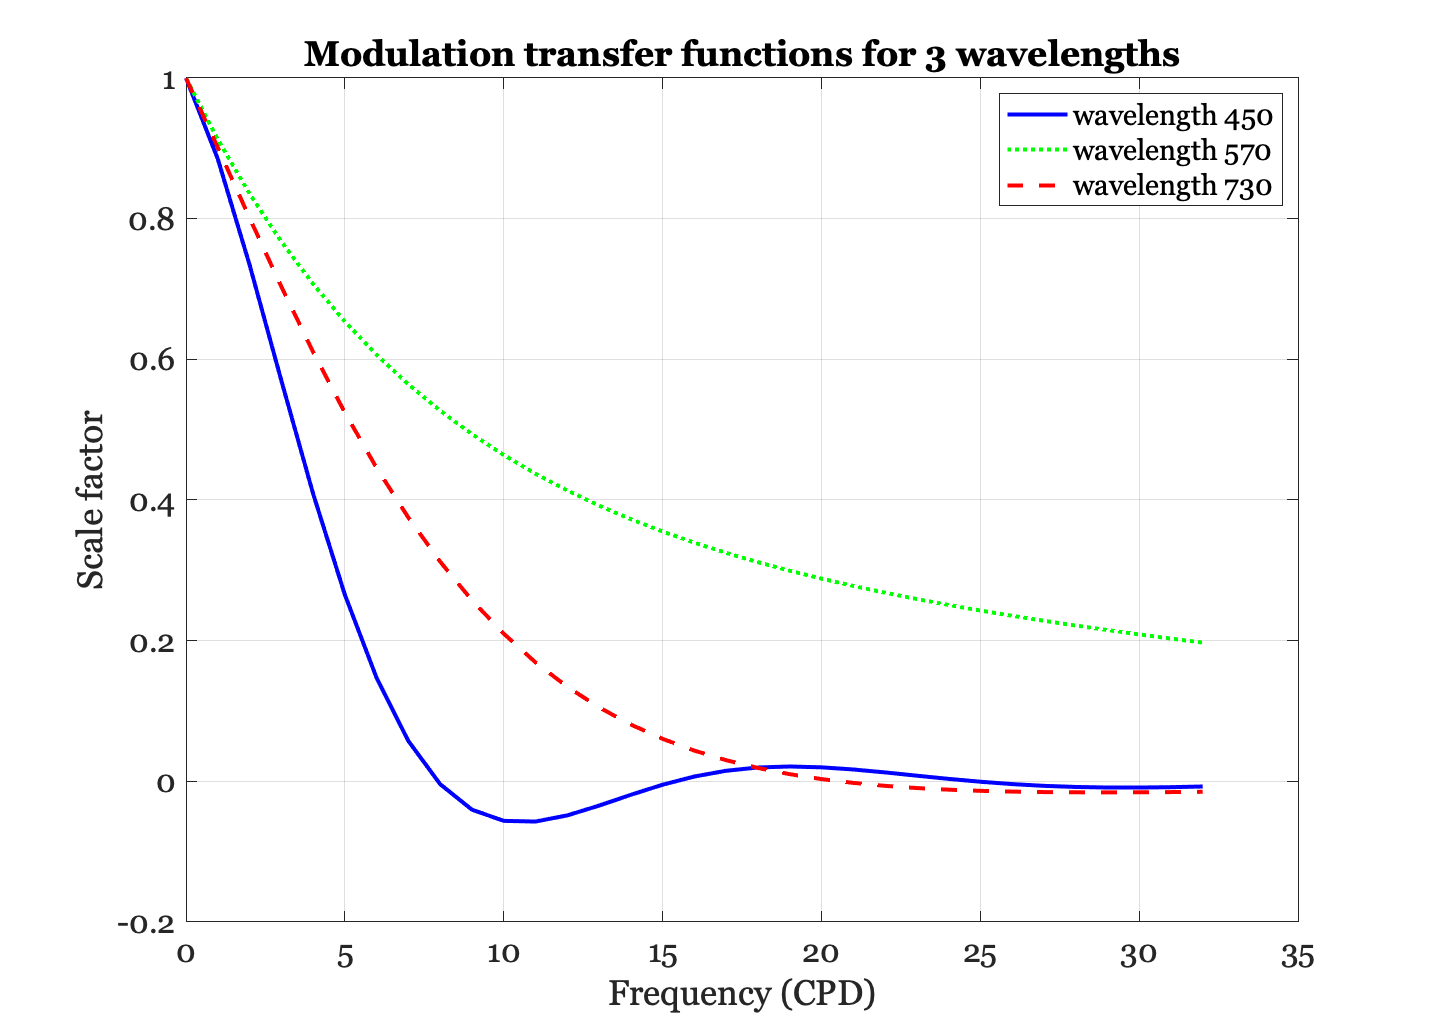

load('combinedOtf','combinedOtf','sampleSf');

% Here is a graph of the MTFs at different wavelengths.  The differences reflect
% the chromatic aberration of the human eye.
ieNewGraphWin;
plot(sampleSf, combinedOtf(81, :), 'b-', ...
    sampleSf, combinedOtf(201,:), ...
    'g:', sampleSf, combinedOtf(361, :), 'r--' ,...
    'linewidth',2);
legend('wavelength 450', 'wavelength 570','wavelength 730');
xlabel('Frequency (CPD)'); ylabel('Scale factor'); grid on
title('Modulation transfer functions for 3 wavelengths');

## Observation

Notice that the amplitude of the short-wavelength becomes negative. This occurs because the blurring is so severe that the harmonic function is reproduced in the opposite phase compared to the input harmonic.  Hence, the amplitude is represented by a negative number.  This can be illustrated using slide projector, and the phenomenon is called "spurious resolution."

## More modern Linespreads, Pointspreads, and MTFs

Ijspeert and others in the Netherlands developed a more extensive set of functions to predict the basic image formation variables in the average human eye.  The curves they derived were based on empirical inspection of data sets, and do not have any strong theoretical foundation. Still, they are probably more accurate than the Westheimer function and they are parameterized for the subject's age, pigmentation, and pupil diameter. Hence, for practical computation, these are probably more useful.

age = 20;               % Subject's age
pupil = 1.5; 		% diameter in mm
pigmentation = 0.142; 	% Caucasian
freqIndexRange = 1:50; 	% The spatial frequency range

% Set the span to be 1 deg, so we know that 1 cycle in the MTF
% corresponds to 1 cycle per deg
angleInDeg = (-.25:.005:.25);
angleInSec = angleInDeg*3600;
angleInRad = deg2rad(angleInDeg);

[iMTF, iPSF, iLSF] = ijspeert(age, pupil, pigmentation, ...
    freqIndexRange, angleInRad);

% The functions should be normalized so that the area under the
% linespread and the first value of the MTF are one.
iMTF = iMTF/iMTF(1);
iLSF = iLSF/sum(iLSF);


These are the modulation transfer function and linespread for the ijspeert calculation

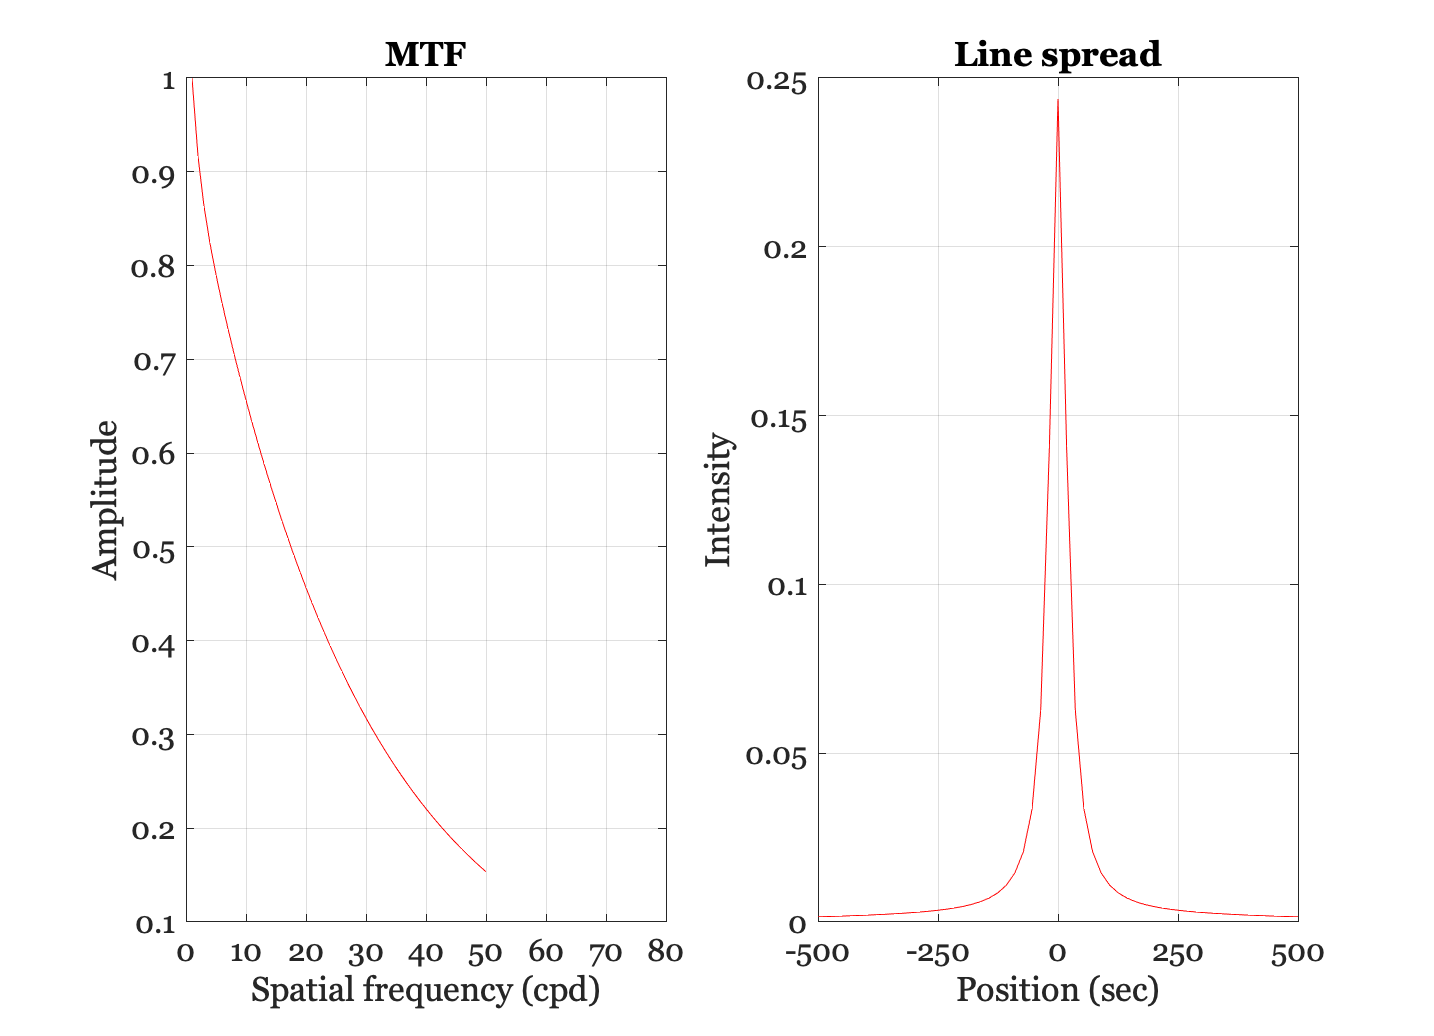

ieNewGraphWin; %clf
subplot(1,2,1), plot(iMTF); grid on
set(gca,'xtick',(0:10:80),'xlim',[0 80]);
xlabel('Spatial frequency (cpd)');
ylabel('Amplitude');
title('MTF')

% Here is the linespread function
subplot(1,2,2), plot(angleInSec,iLSF); grid on
xlabel('Position (sec)');
ylabel('Intensity');
set(gca,'xtick',(-500:250:500),'xlim',[-500 500]);
title('Line spread')

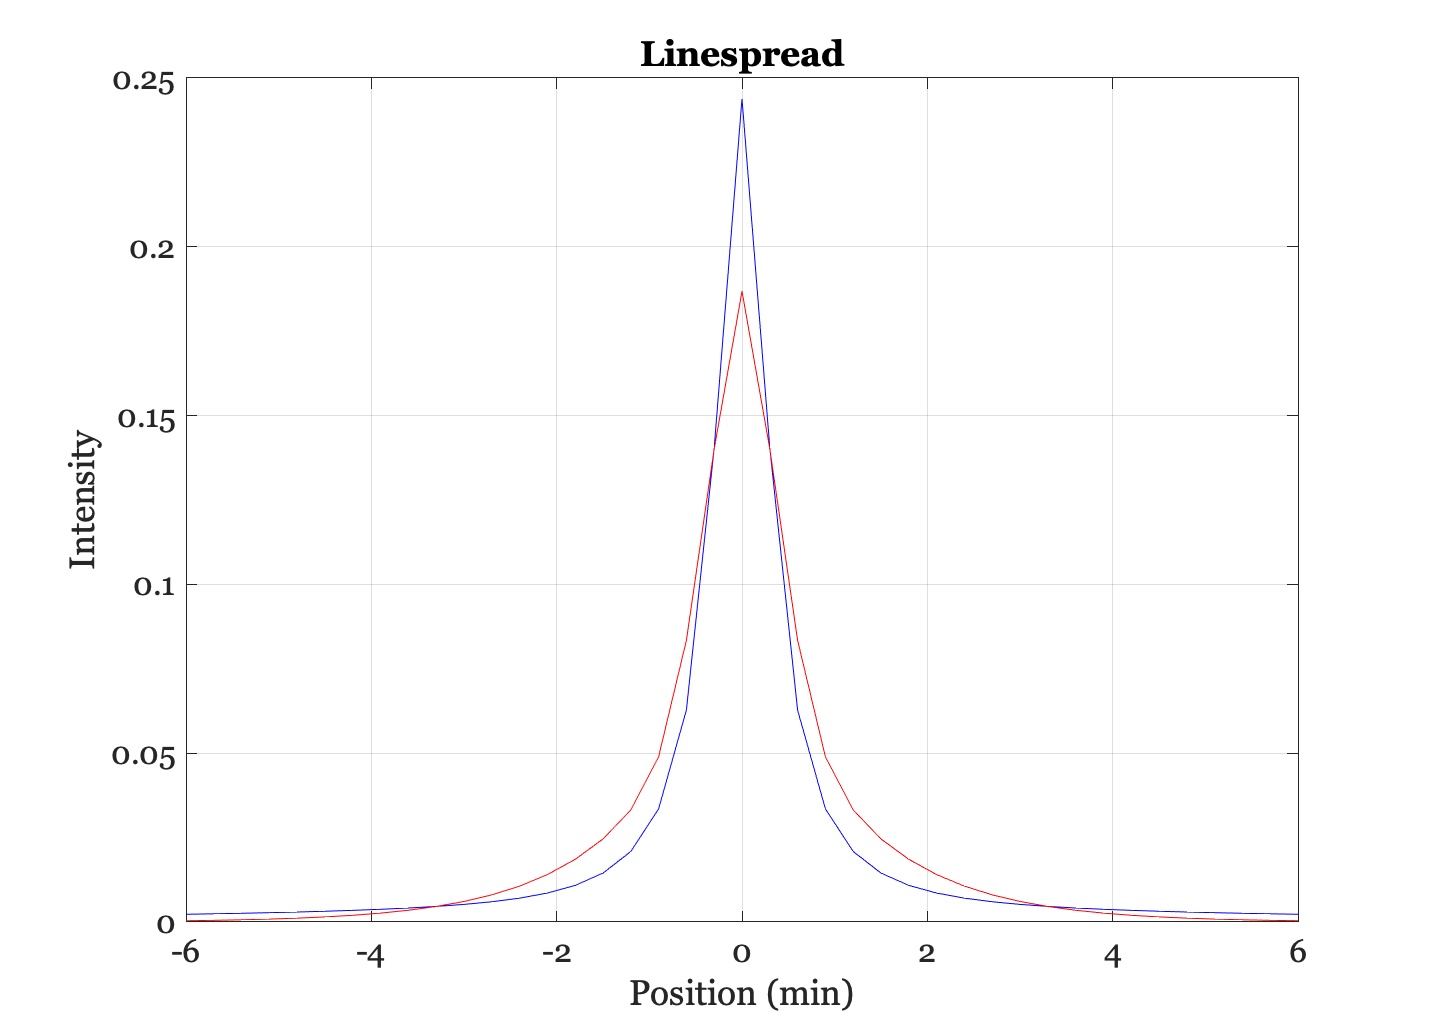


% We can compare the ijspeert and westheimer linespread functions
xMin = angleInSec/60;
ls = 0.47*exp(-3.3 *(xMin.^2)) + 0.53*exp(-0.93*abs(xMin));
ls = ls / sum(ls);
westMTF = abs(fft(ls));

ieNewGraphWin;
plot(angleInSec/60,iLSF,'b-',angleInSec/60,ls,'r-')
set(gca,'xtick',(-8:2:8),'xlim',[-6 6]);
xlabel('Position (min)'), ylabel('Intensity'), title('Linespread')
grid on

## Comparison of the MTFs with the Williams data

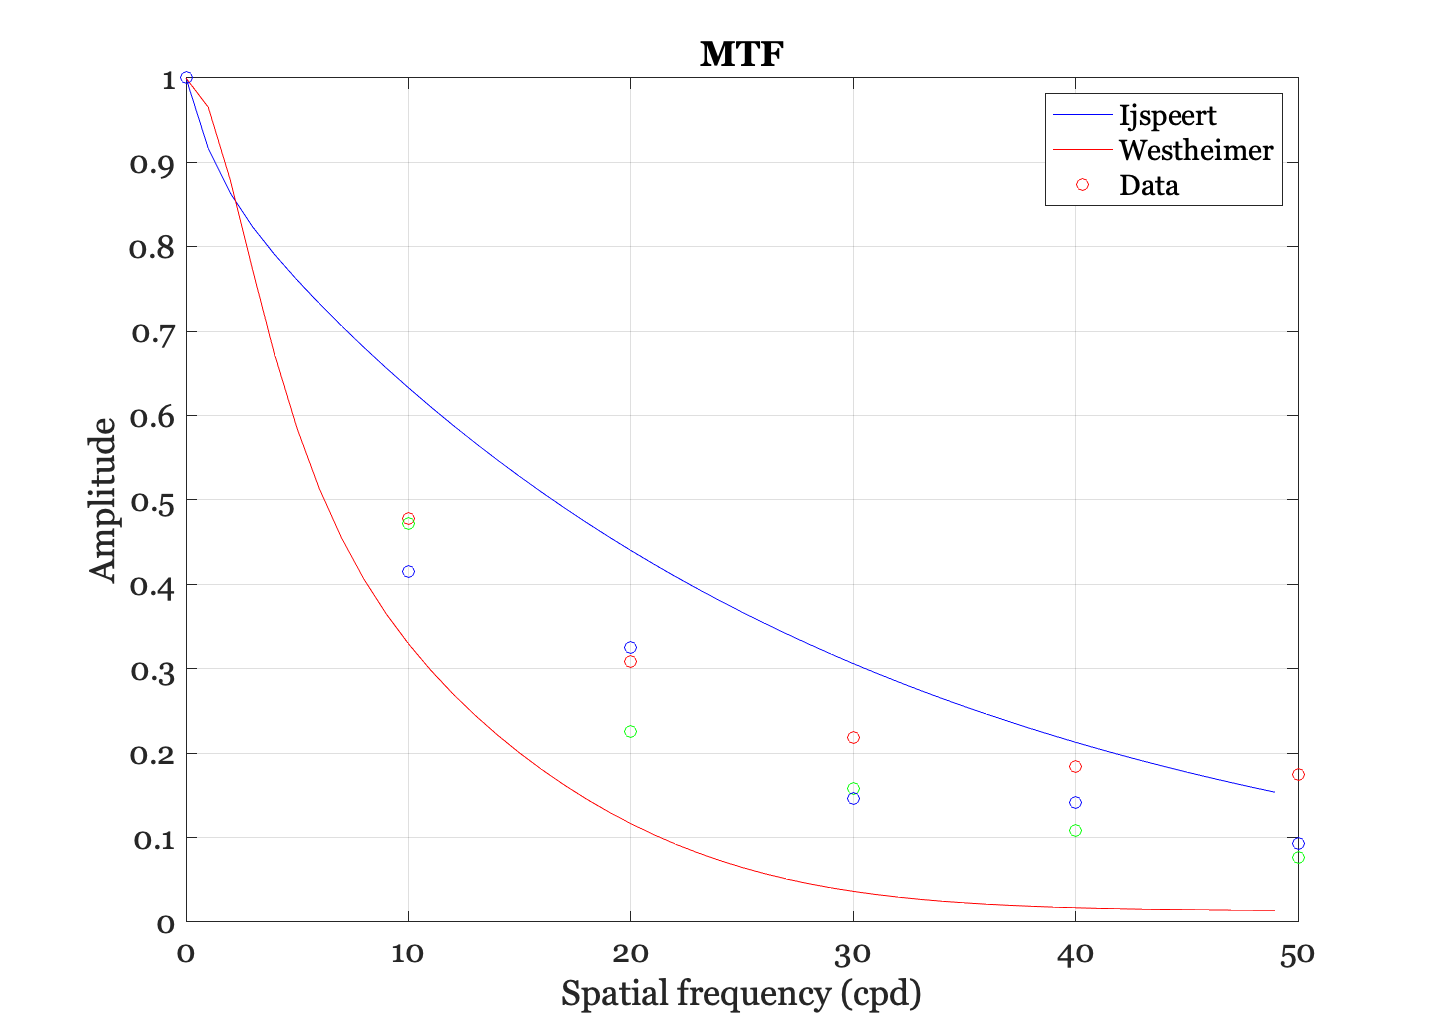

% Data from colleagues
load('williams','dhb','drw','rnb','dataF');

ieNewGraphWin;
n = length(iMTF);
freq = 0:(n-1);
plot(freq,iMTF(1:n),'b-',freq,westMTF(1:n),'r-')
hold on
plot(dataF,dhb,'ro',dataF,drw,'go',dataF,rnb,'bo')
xlabel('Spatial frequency (cpd)'), ylabel('Amplitude'), title('MTF')
set(gca,'ylim',[0 1])
grid on; hold off; legend('Ijspeert','Westheimer','Data')

## What does the pointspread function look like in 2D?

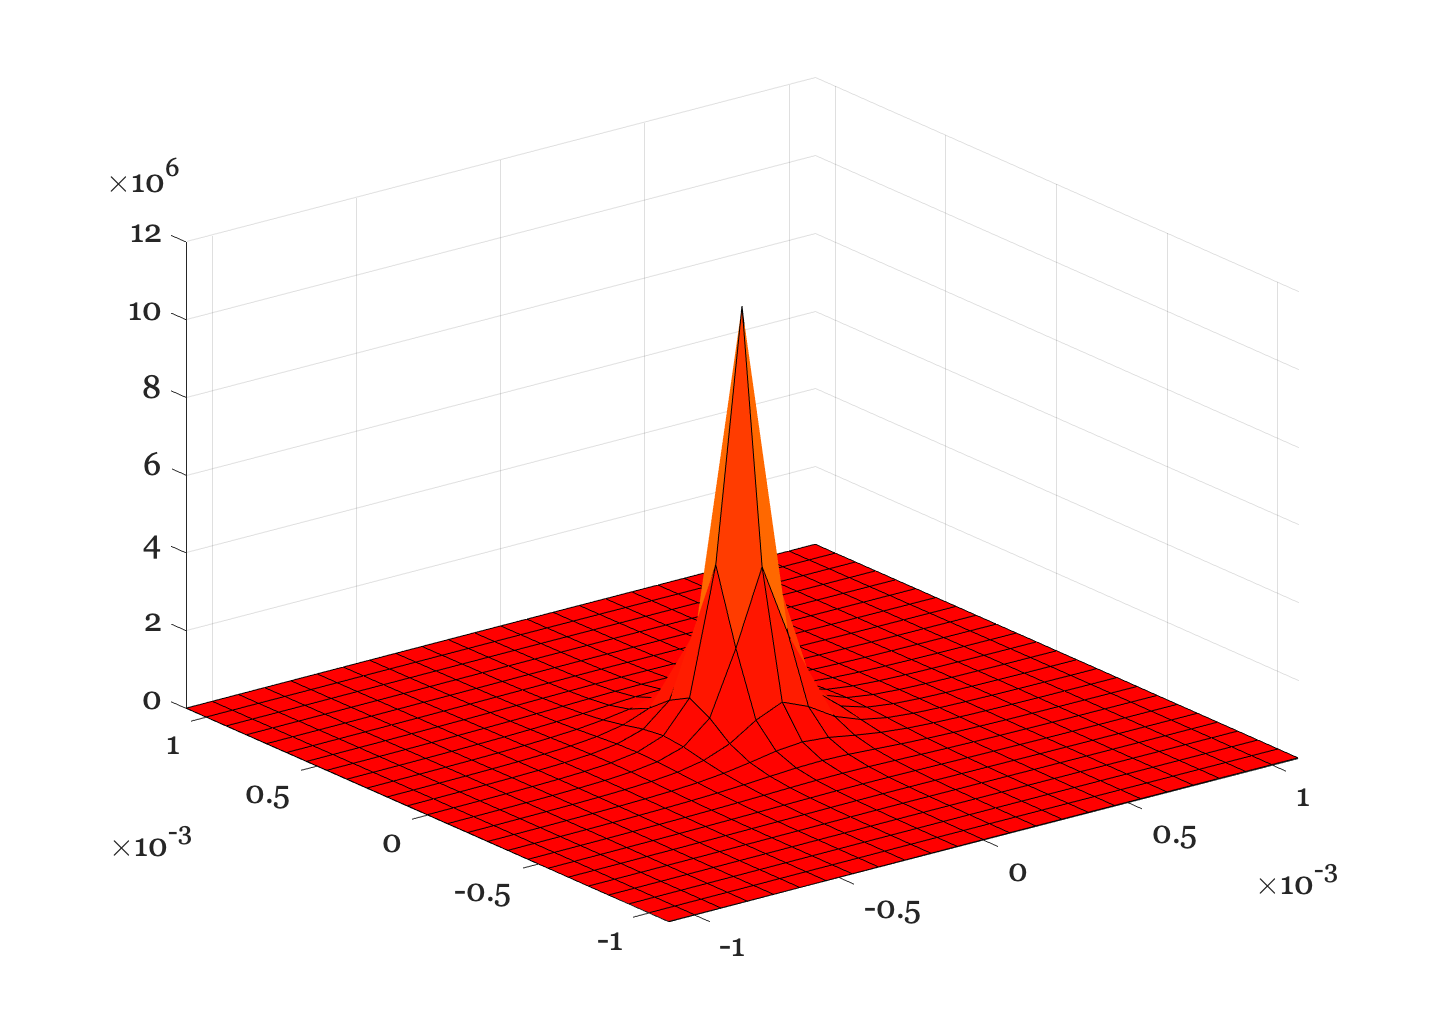

% The PSF is circularly symmetric.  So, we can accumulate
% the 1D values into a 2D surface.
angleInRad2D = linspace(min(angleInRad)/4,max(angleInRad)/4,length(angleInRad)/4);
nSamples = length(angleInRad2D);
[X,Y] = meshgrid(angleInRad2D,angleInRad2D);

% Because the pointspread function is symmetric, we can calculate the value by
% building a matrix D that measures only the distance from the center of matrix.
% Try plotting this distance matrix using the command:
%
%   imagesc(D); colorbar; axis image
%
D = sqrt(X.^2 + Y.^2);

% Now, loop through the rows of D to calculate the pointspread values
% as a function of angle.
iPSF2D = zeros(size(D));
for ii=1:nSamples
    a = D(ii,:);
    [iMTF, iPSF2D(ii,:)] = ijspeert(age, pupil, pigmentation, ...
        freqIndexRange, a);
end

ieNewGraphWin;
colormap(autumn(128));
surf(angleInRad2D,angleInRad2D,iPSF2D);

## Using ISET to visualize defocus of diffraction limited optics

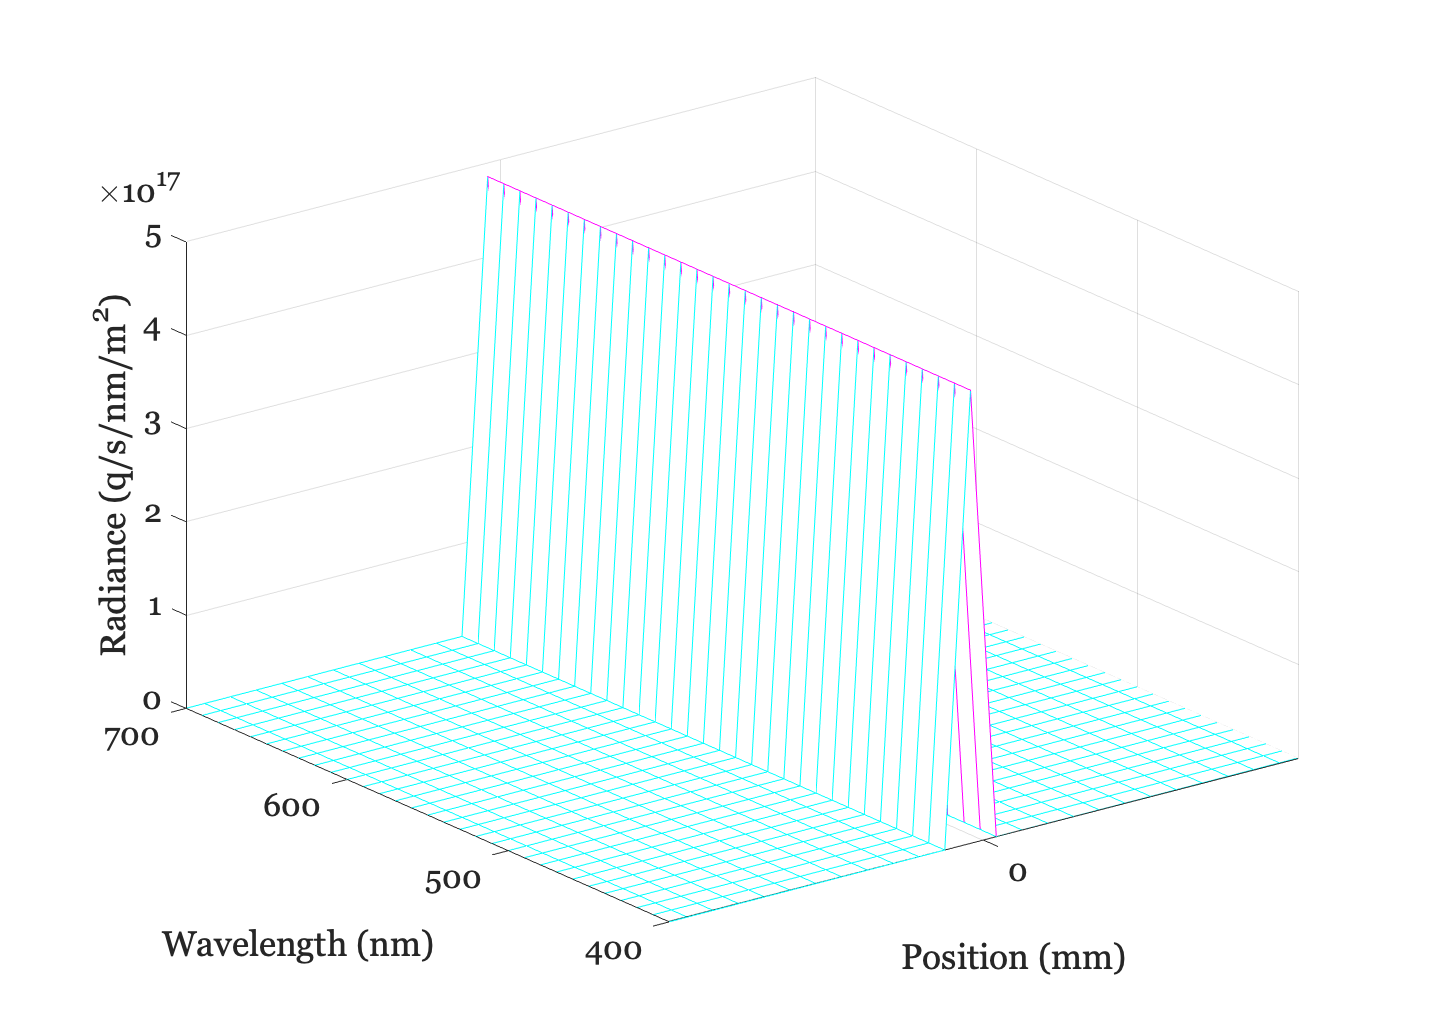

% Create a scene comprising a multispectral line, with equal photons
scene = sceneCreate('line ep',128);    % A thin line, equal photon radiance at each wavelength
scene = sceneSet(scene,'fov', 0.5);    % Small field of view (deg)
sceneWindow(scene);       % Save it in the database and show

% Plot the scene data
scenePlot(scene,'radiance hline',[64 64]);
set(gca,'xlim',[-1 1]);  % Plot radiance at central 1 mm


% Type doc scenePlot to see other plotting options

## Simulate the line passing through diffraction-limited optics

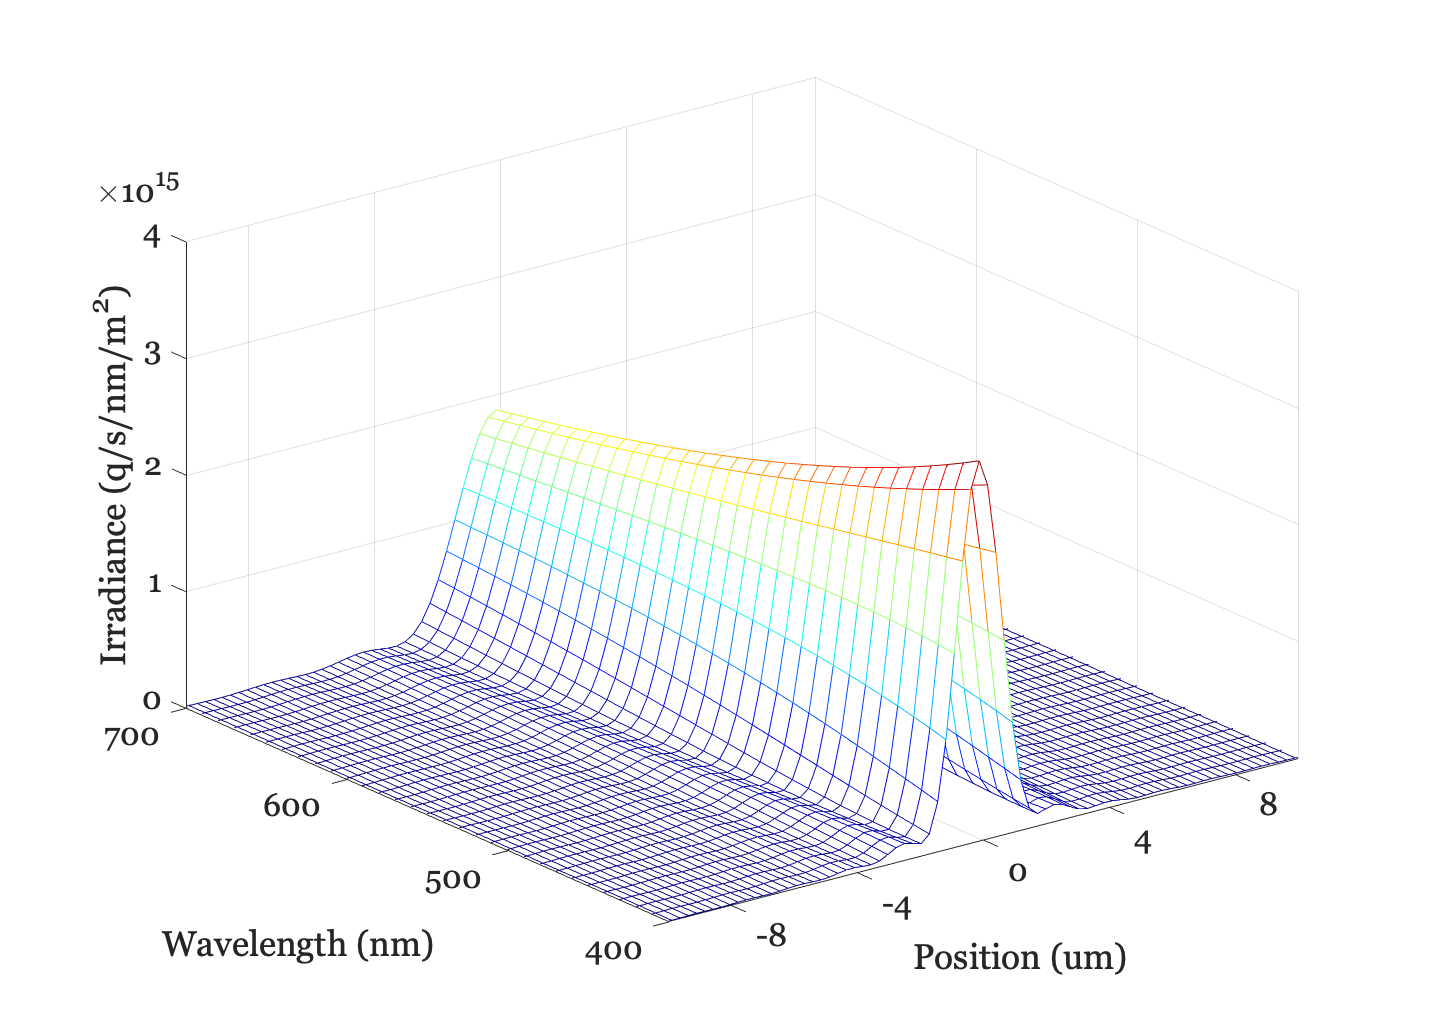

oi = oiCreate;               % Default optics is diffraction limited
oi = oiCompute(oi,scene);
oiWindow(oi);

% Plot the line spread as a function of wavelength
oiPlot(oi,'irradiance hline',[80 80]);
set(gca,'xlim',[-10 10]);  % Plot radiance at central 10 um

## Now change the f-number of the optics and do it again

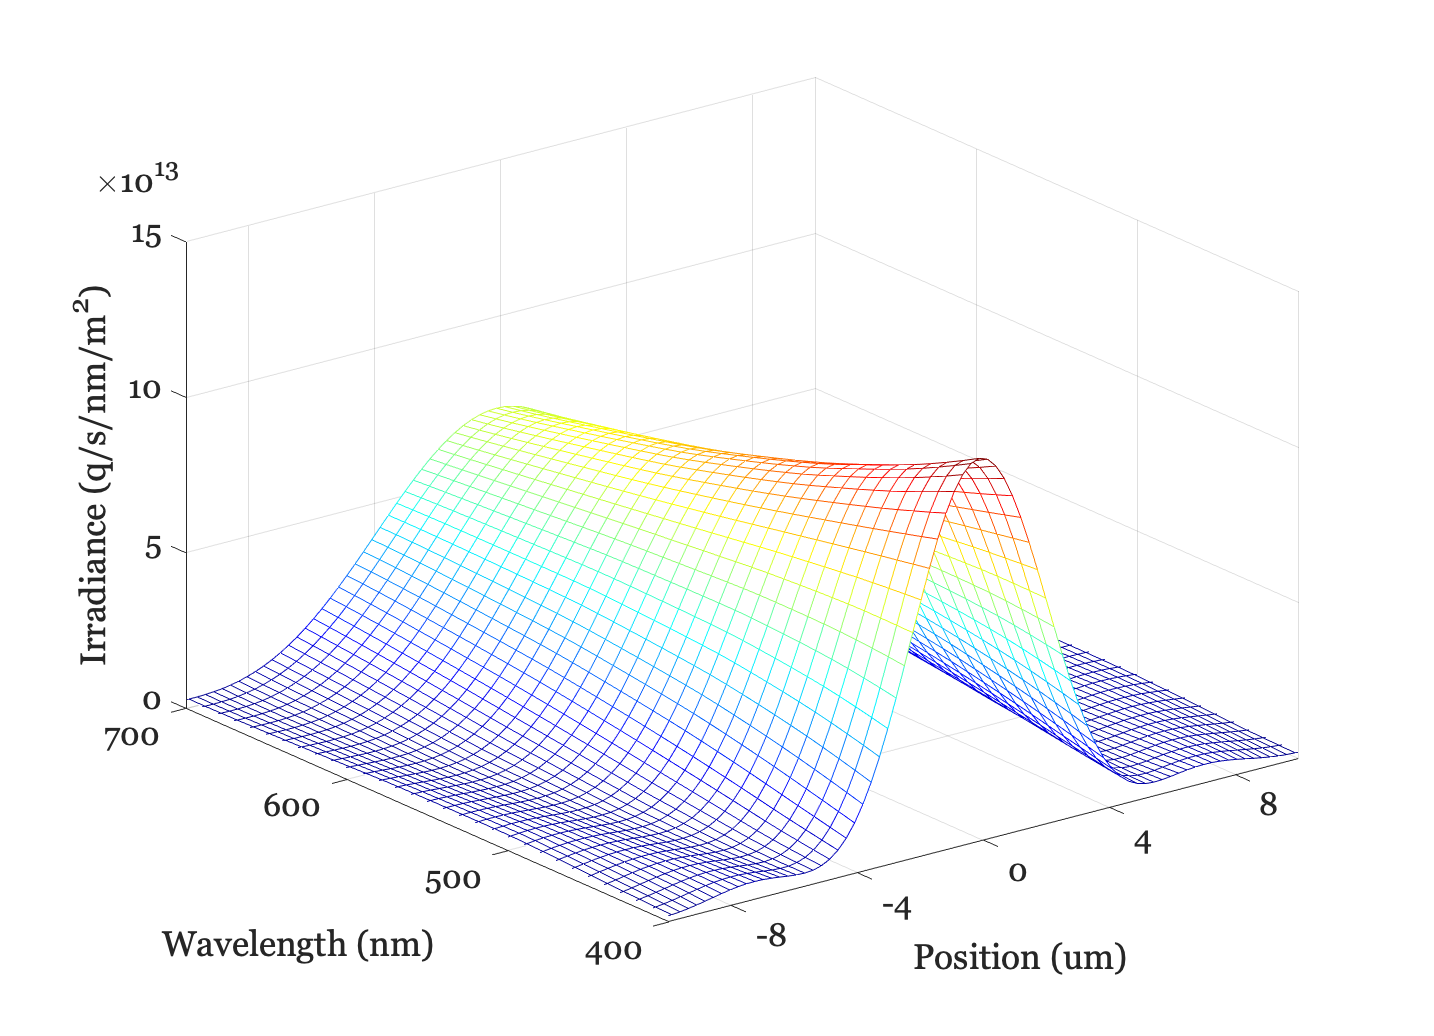

oi = oiSet(oi,'optics fnumber',12);
oi = oiCompute(oi,scene);
oiWindow(oi);

oiPlot(oi,'irradiance hline',[80 80]);
set(gca,'xlim',[-10 10]);  % Plot radiance at central 1 mm

## Questions to Think About

At this point, you can answer most of the questions in "Homework 1: Image Formation."  A few of the questions will involve material from the Videos or perhaps looking something up in the FOV readings.